# Looking at activity of cells compared to state metrics

NOTE (JR 01/31/23): Need to correct time since movement for animals from Geoffrey as the treadmill is z-scored and the threshold used will not work

% load cell IDs for cells recorded across multiple days
load('D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\SST_nNOS_sleep_imaging\cellIDs.mat')
load('D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\SST_nNOS_sleep_imaging\cellIDs_sleep.mat')

% Options for data alignment
ops.cameraTriggerChan = 11;
ops.treadmillChan = 14;
ops.overwrite = false;
ops1.method = 'baseline';

## Animal 4612

Animal 4612 Day 1

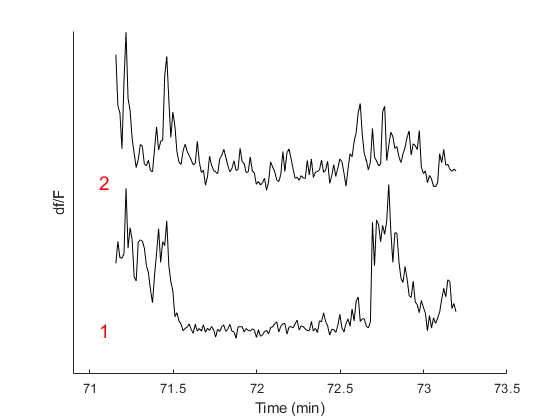

basepath = 'G:\sleep_wake_recordings\4612\JR_21_12_02_confon_GCaMP_4612\JR_21_12_02_confon_GCaMP_4612_211202_135703';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4612\JR_21_12_02_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

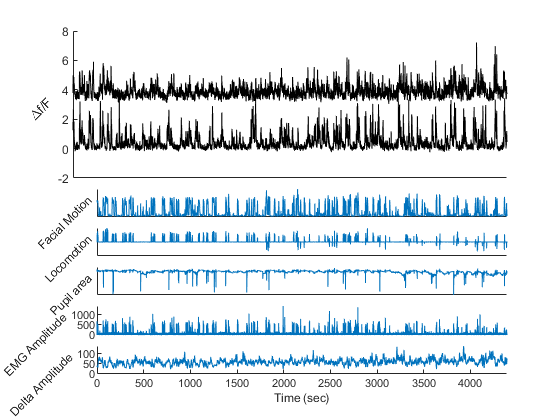


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

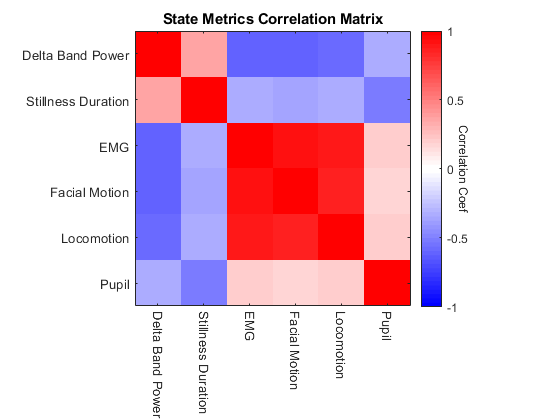

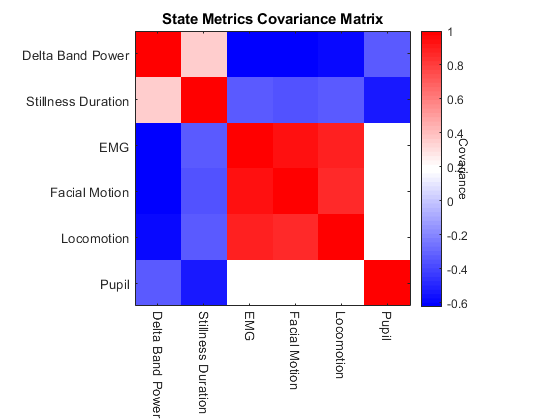

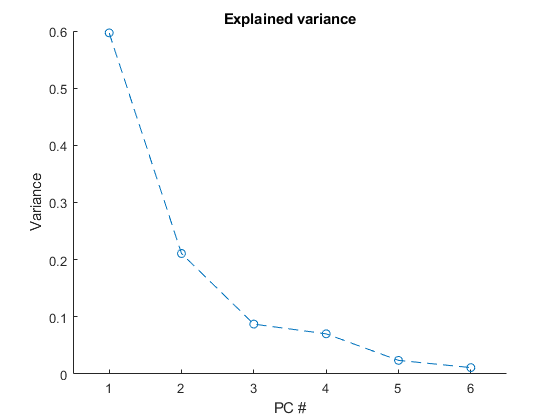

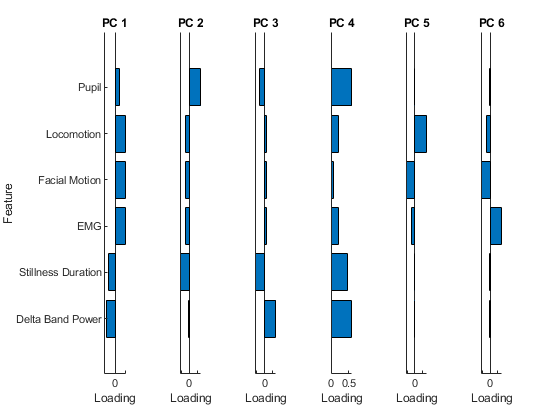

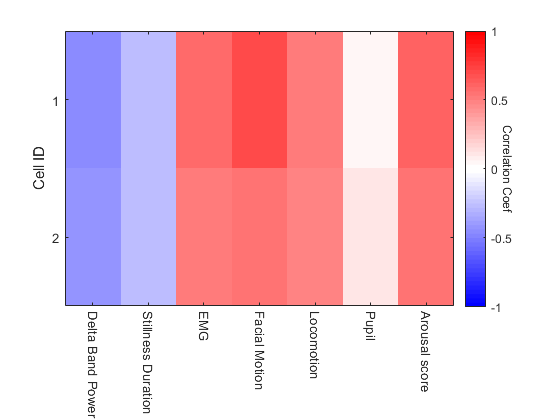

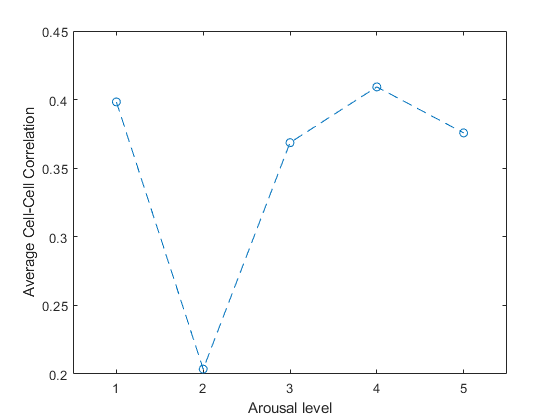


% Add cell IDs and Animal ID
imgStruct.cellIDs = Animal4612(1).cellIDs;
imgStruct.AnimalID = '4612';

% Analyze session
Animal4612(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4612 Day 2

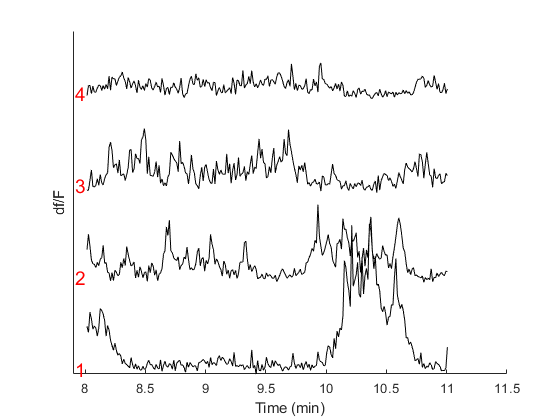

basepath = 'G:\sleep_wake_recordings\4612\JR_21_12_07_confon_GCaMP_4612_2\JR_21_12_07_confon_GCaMP_4612_211207_140953';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4612\JR_21_12_07_confon_GCaMP_4612_2\field1_001';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

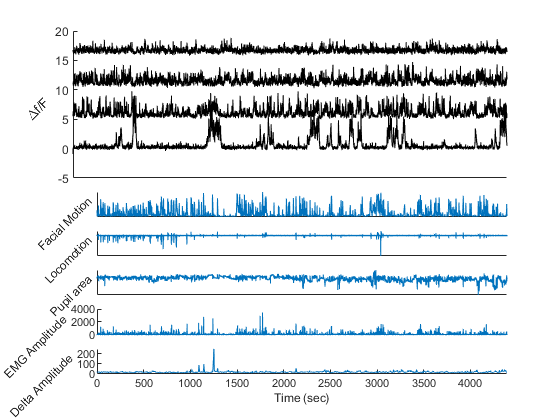


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

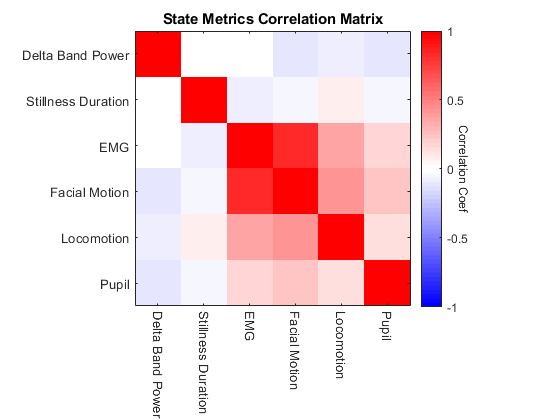

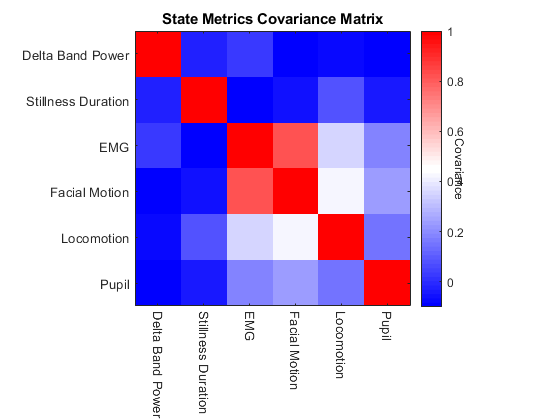

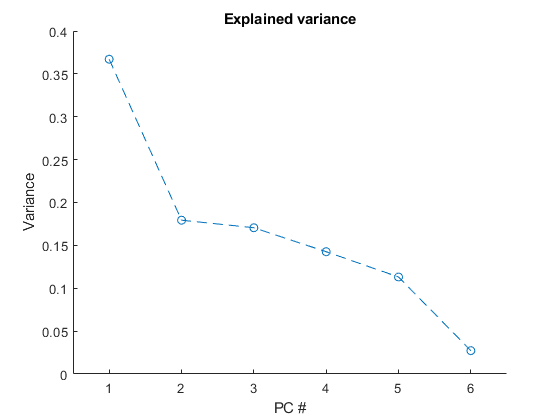

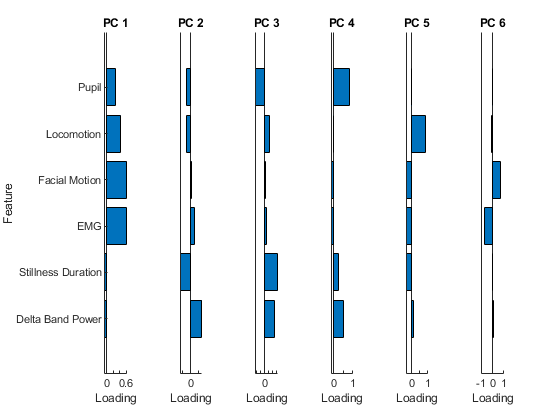

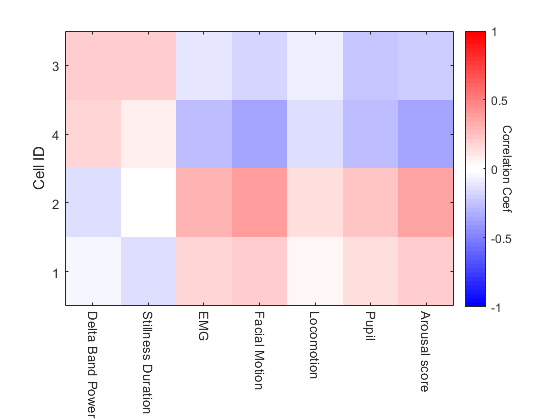

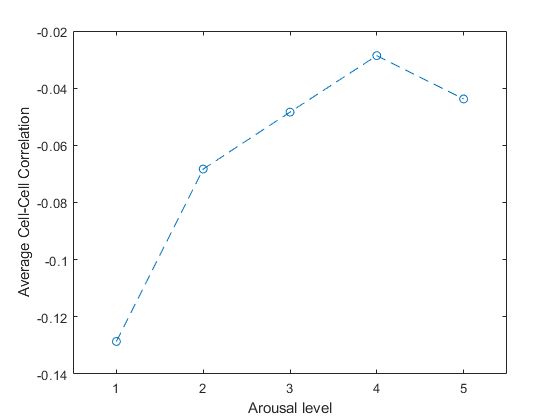


% Add cell IDs
imgStruct.cellIDs = Animal4612(2).cellIDs;
imgStruct.AnimalID = '4612';

% Analyze session
Animal4612(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4612 Day 3

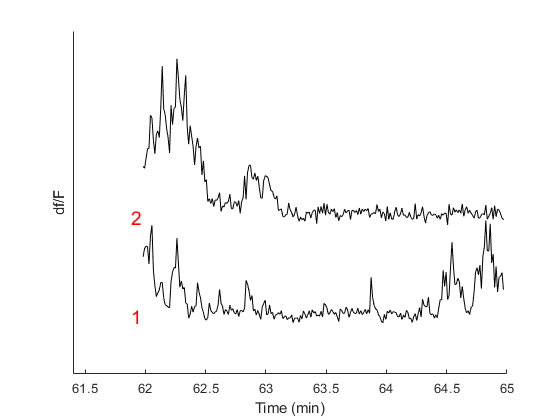

basepath = 'G:\sleep_wake_recordings\4612\JR_21_12_10_confon_GCaMP_4612\JR_21_12_10_confon_GCaMP_4612_211210_130217';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4612\JR_21_12_10_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

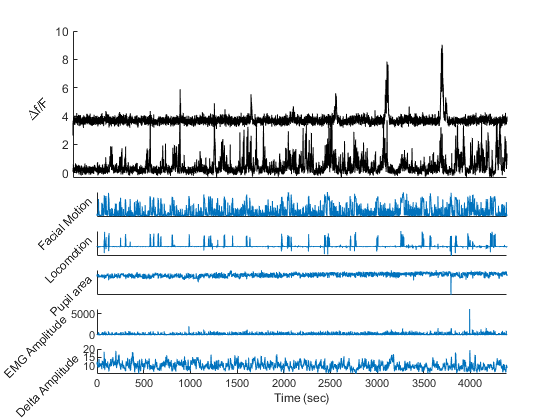


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

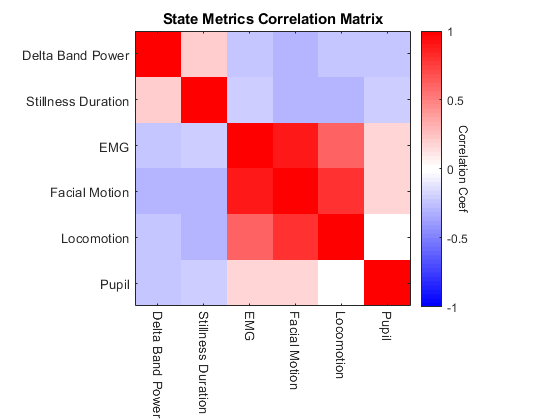

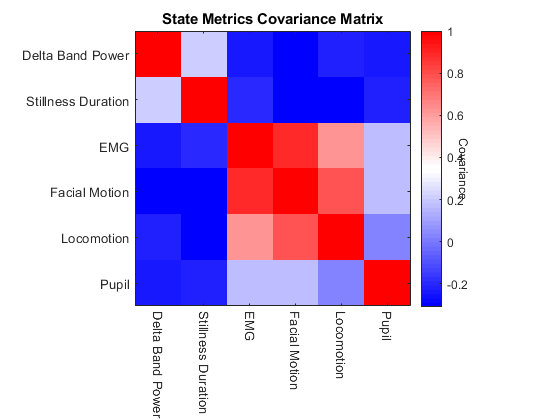

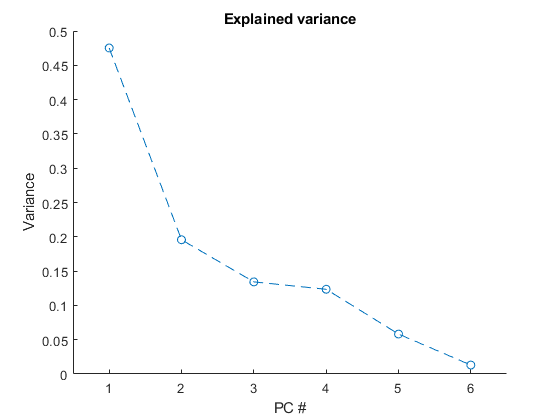

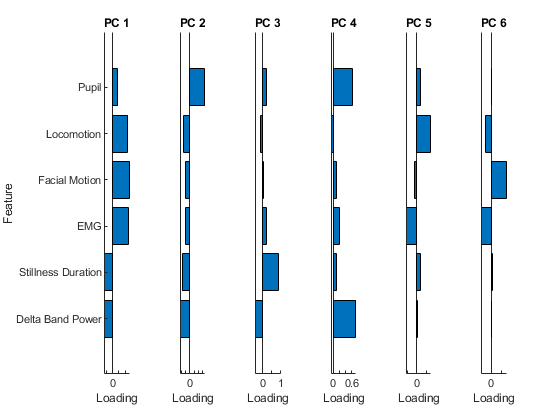

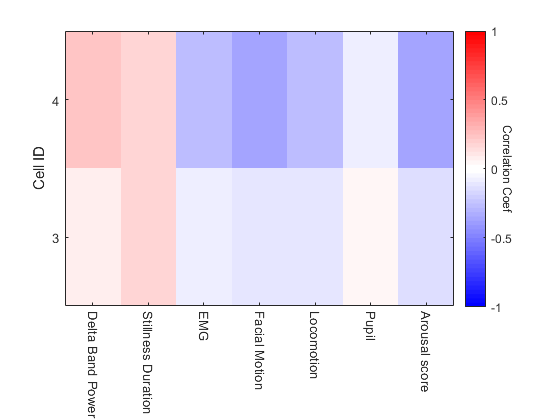

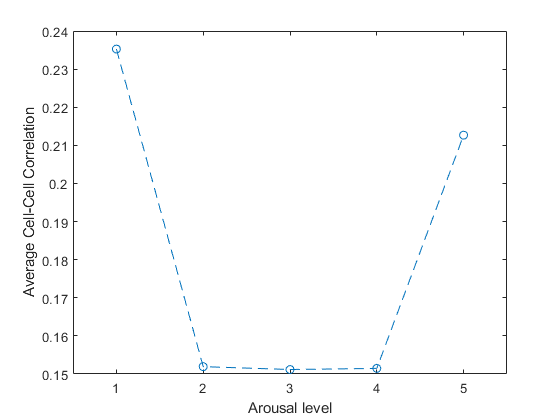


% Add cell IDs
imgStruct.cellIDs = Animal4612(3).cellIDs;
imgStruct.AnimalID = '4612';

% Analyze session
Animal4612(3).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4612 Day 4

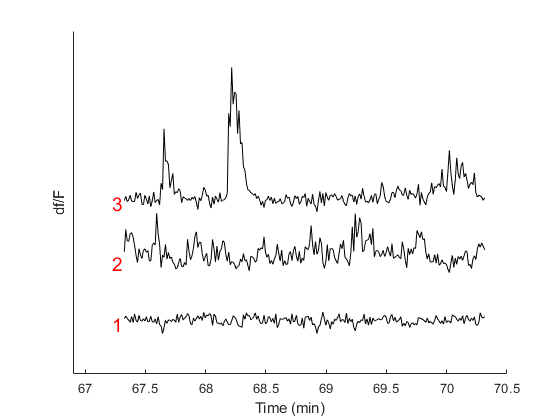

basepath = 'G:\sleep_wake_recordings\4612\JR_21_12_14_confon_GCaMP_4612\JR_21_12_14_confon_GCaMP_4612_211214_145056';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4612\JR_21_12_14_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

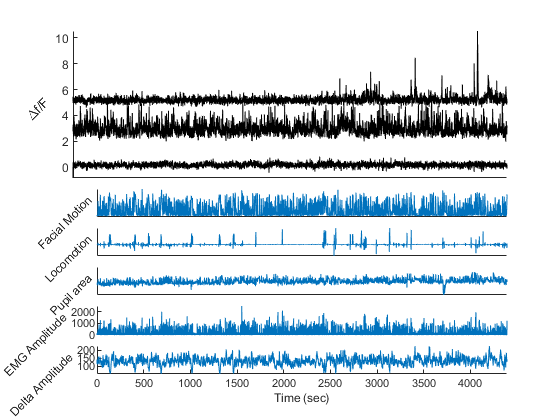


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

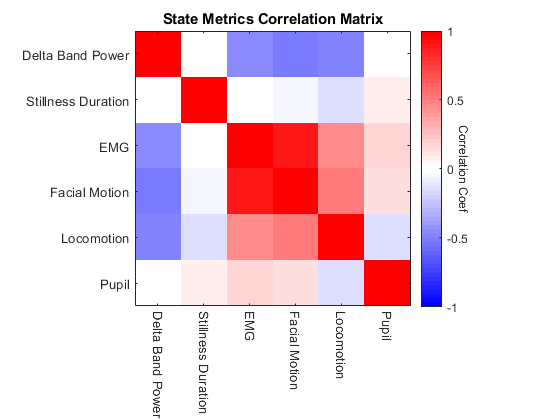

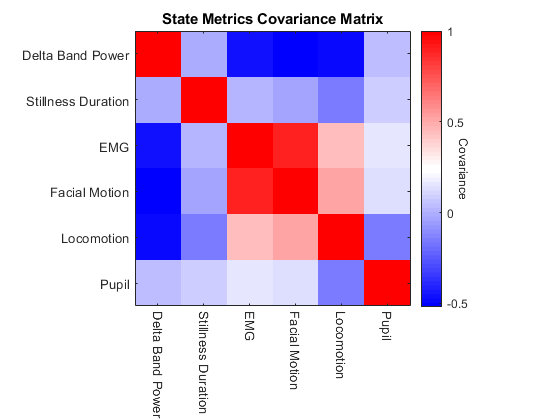

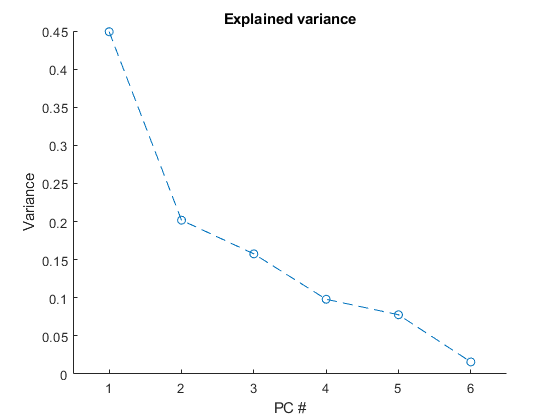

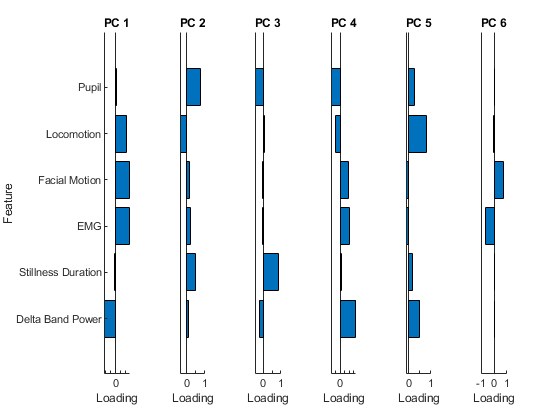

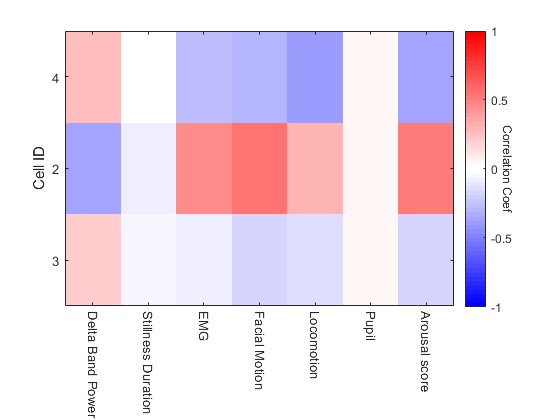

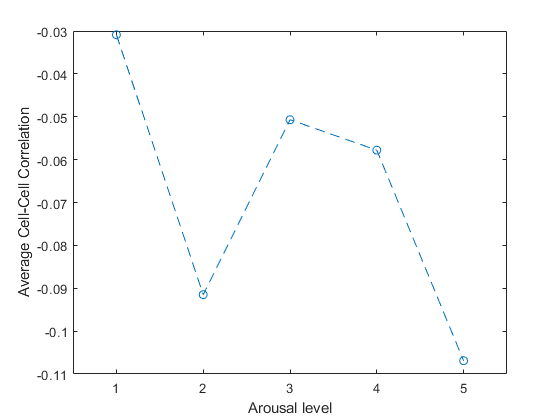


% Add cell IDs
imgStruct.cellIDs = Animal4612(4).cellIDs;
imgStruct.AnimalID = '4612';

% Analyze session
Animal4612(4).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4612 Day 5 sleep

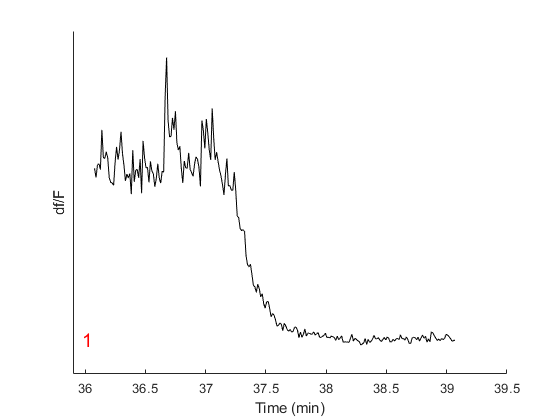

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_03_09_confon_GCaMP_4612\JR_22_03_09_confon_GCaMP_4612_220309_171624';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_03_09_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

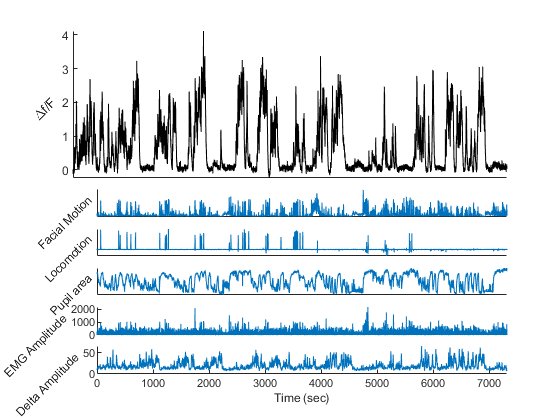


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

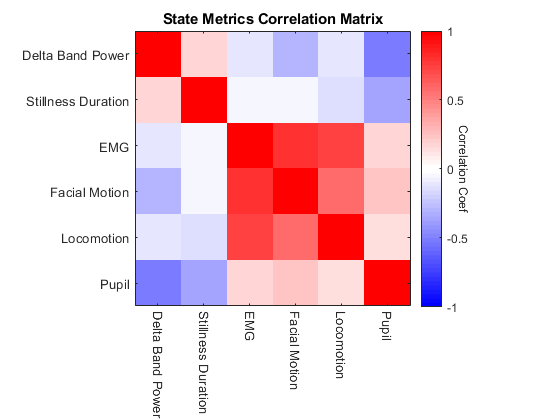

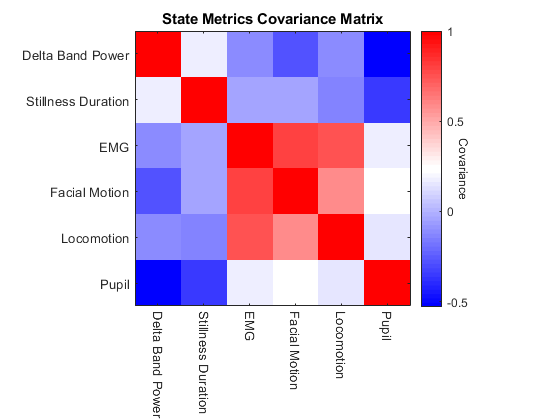

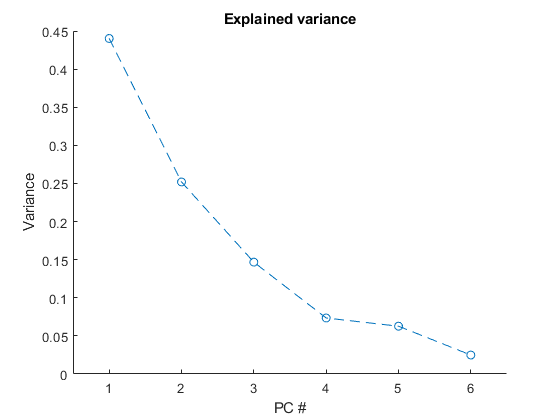

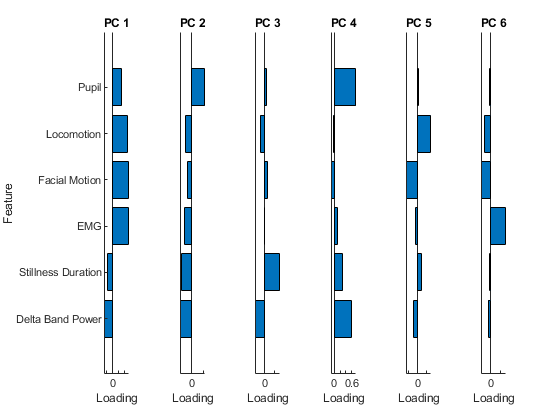

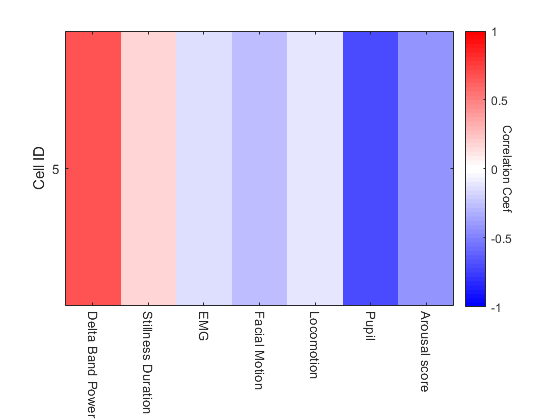

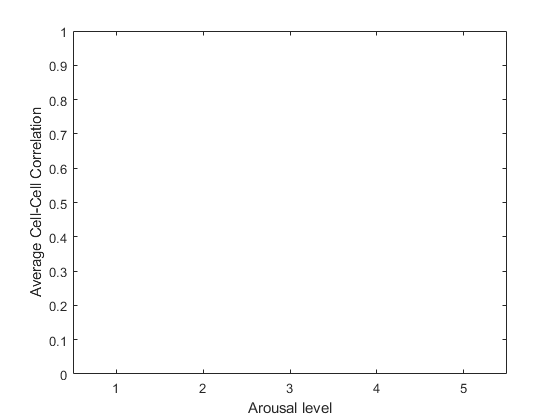


% Add cell IDs
imgStruct.cellIDs = Animal4612_sleep(1).cellIDs;
imgStruct.AnimalID = '4612';

% Analyze session
Animal4612(5).output = analyzeImagingWithoutSleep(imgStruct);

Animal4612(5).cellIDs = imgStruct.cellIDs;

Animal 4612 Day 6 sleep

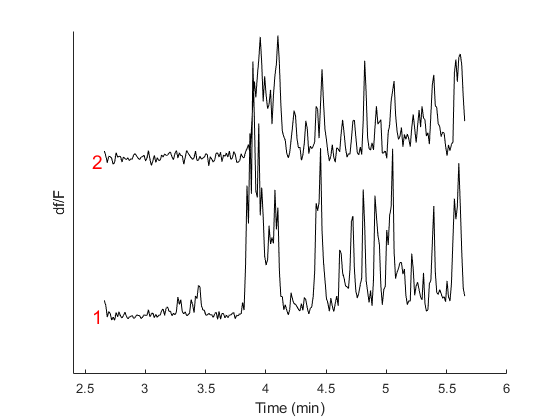

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_11_confon_GCaMP_4612\JR_22_05_11_confon_GCaMP_4612_220511_180252';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_11_confon_GCaMP_4612\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

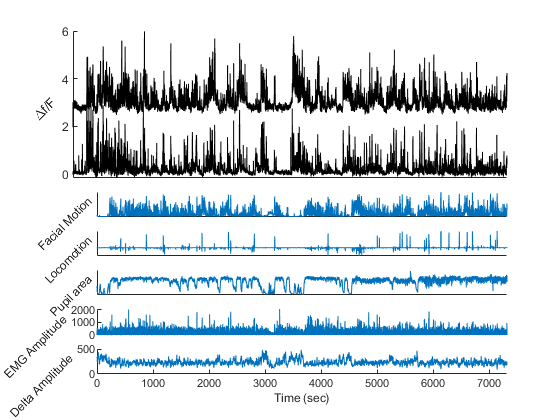


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

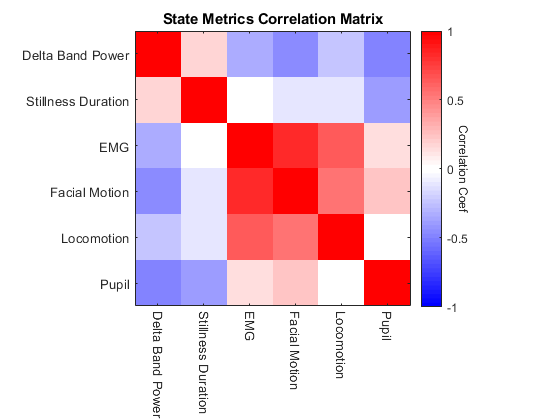

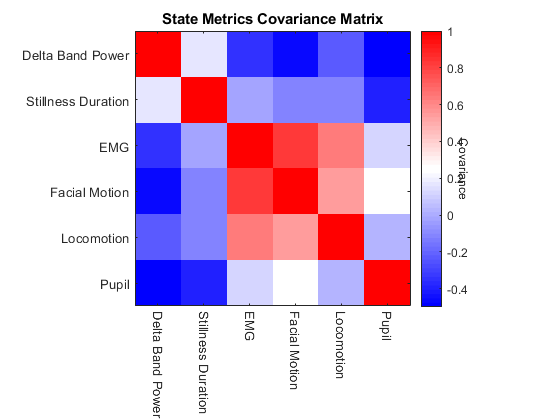

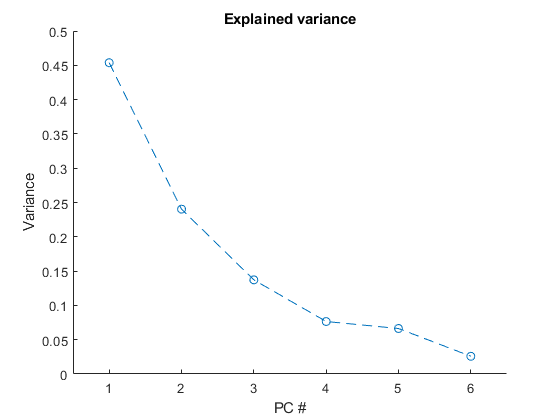

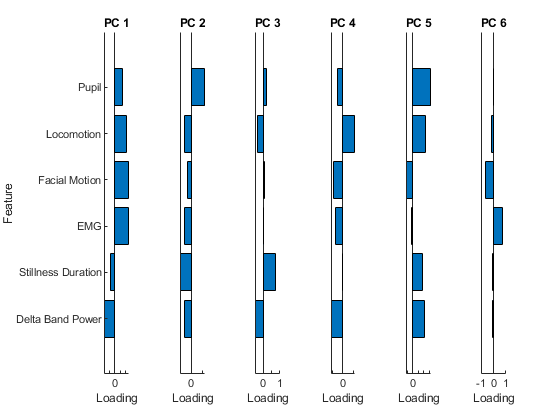

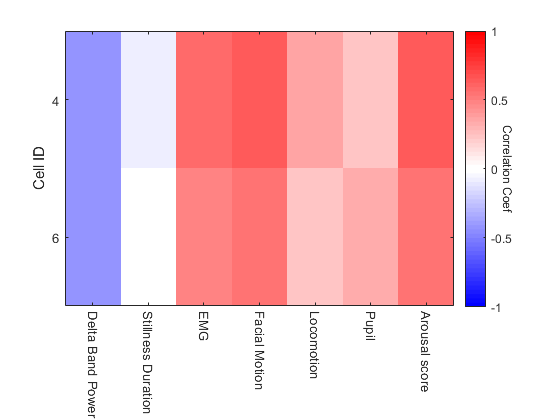

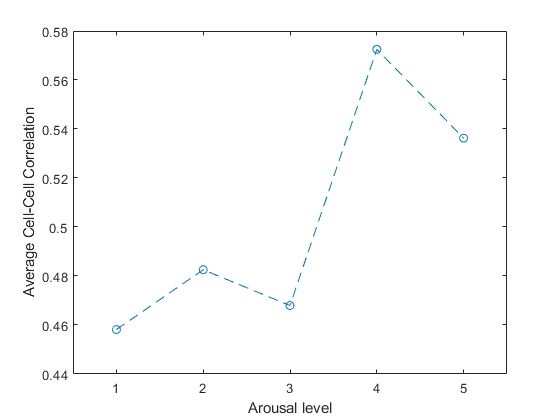


% Add cell IDs
imgStruct.cellIDs = Animal4612_sleep(2).cellIDs;
imgStruct.AnimalID = '4612';

% Analyze session
Animal4612(6).output = analyzeImagingWithoutSleep(imgStruct);

Animal4612(6).cellIDs = imgStruct.cellIDs;

## Animal 4621

Animal 4621 Day 1

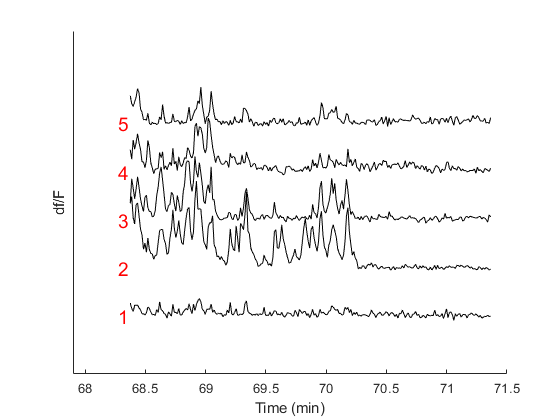

basepath = 'G:\sleep_wake_recordings\4621\JR_21_12_03_confon_GCaMP_4621\JR_21_12_03_confon_GCaMP_4621_211203_133720';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4621\JR_21_12_03_confon_GCaMP_4621\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

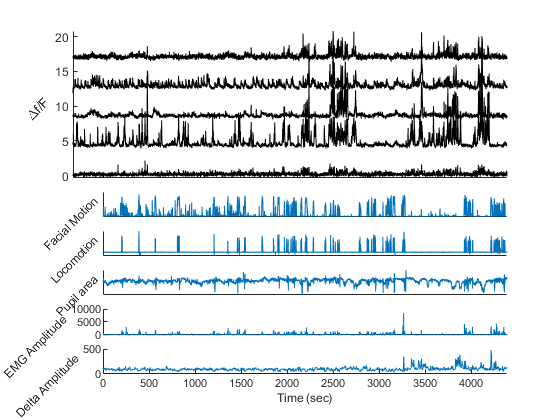


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

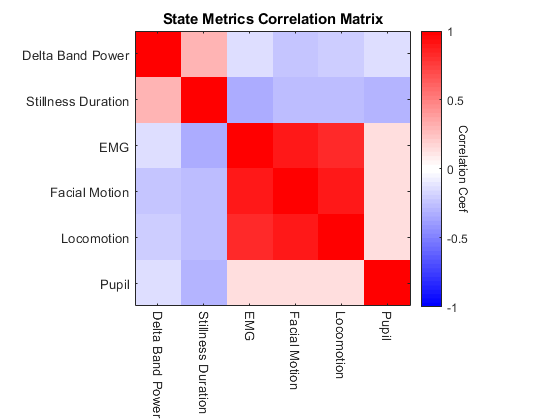

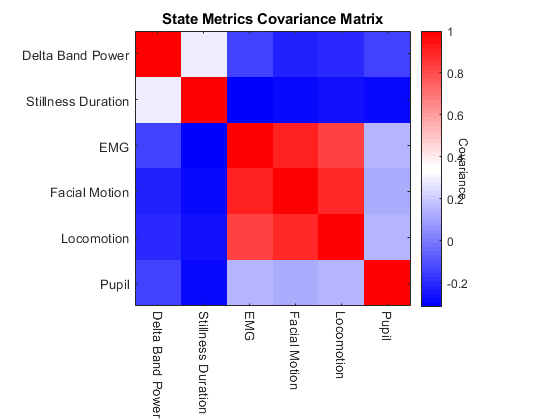

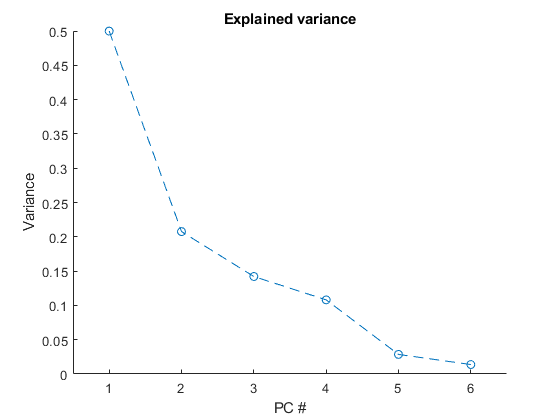

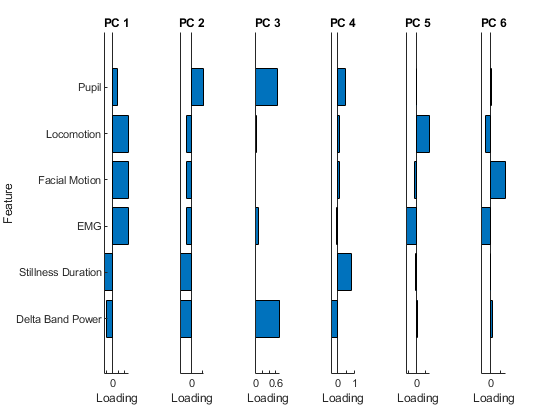

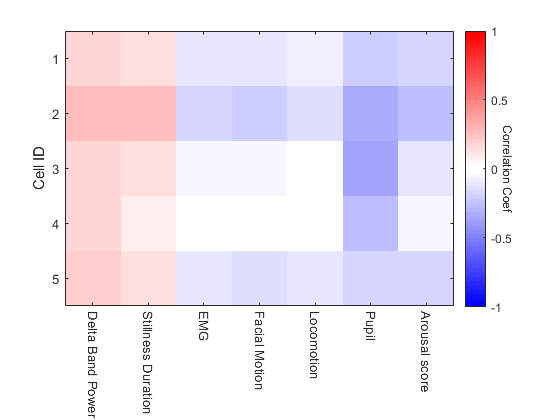

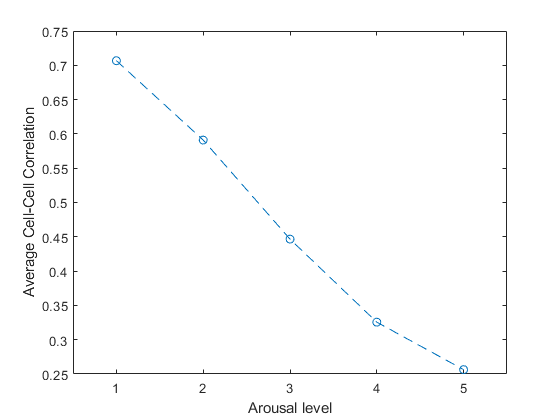


% Add cell IDs
imgStruct.cellIDs = Animal4621(1).cellIDs;
imgStruct.AnimalID = '4621';

% Analyze session
Animal4621(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4621 Day 2

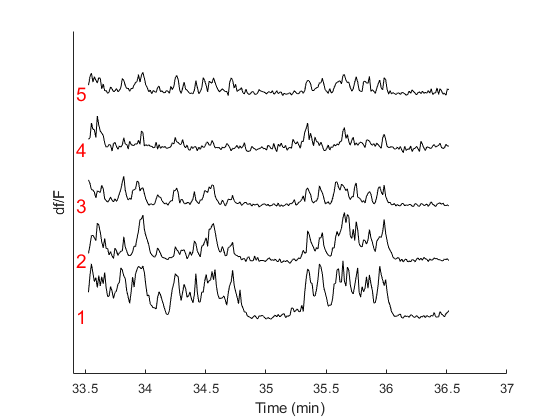

basepath = 'G:\sleep_wake_recordings\4621\JR_21_12_07_confon_GCaMP_4621\JR_21_12_07_confon_GCaMP_4612_211207_161105';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4621\JR_21_12_07_confon_GCaMP_4621\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

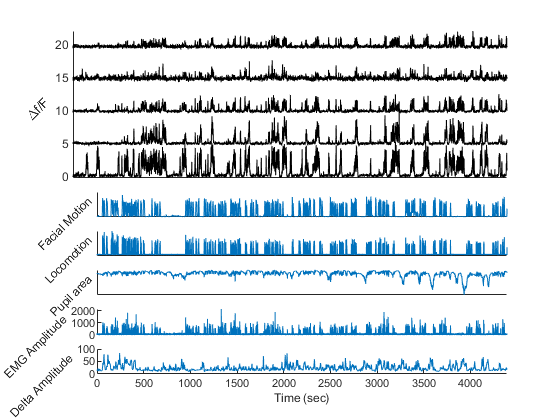


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

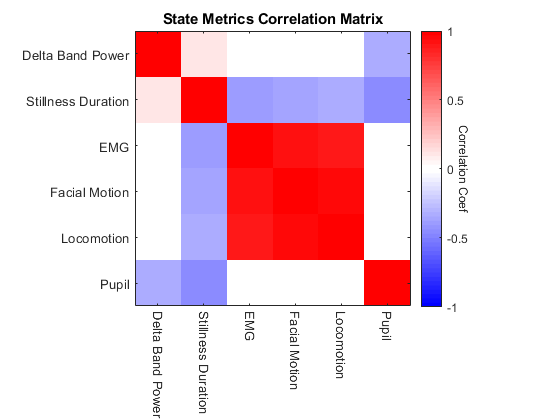

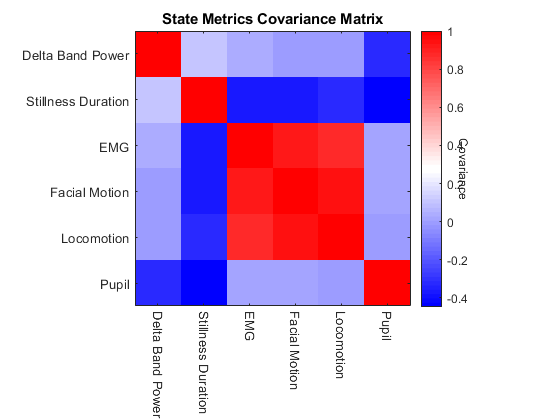

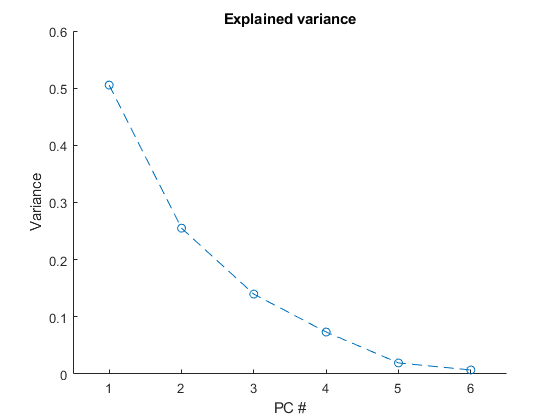

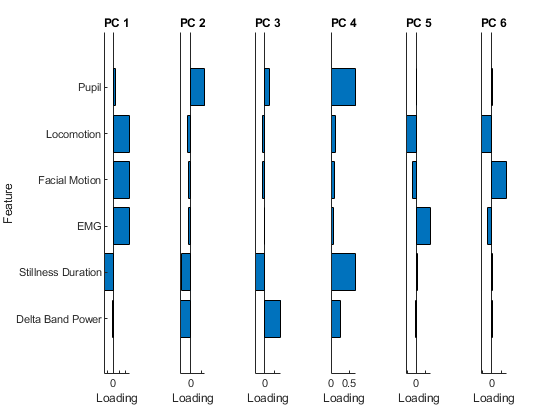

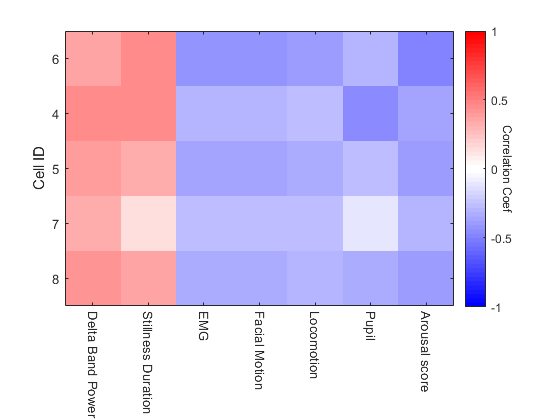

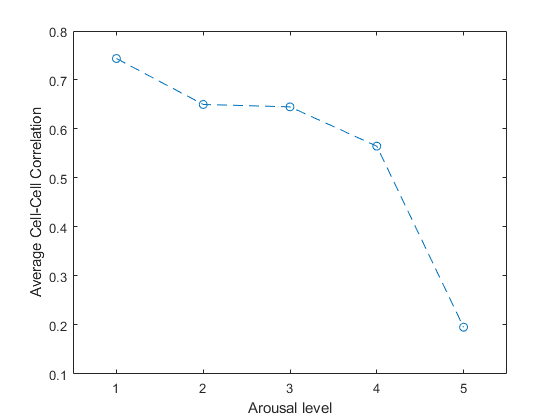


% Add cell IDs
imgStruct.cellIDs = Animal4621(2).cellIDs;
imgStruct.AnimalID = '4621';

% Analyze session
Animal4621(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4621 Day 3

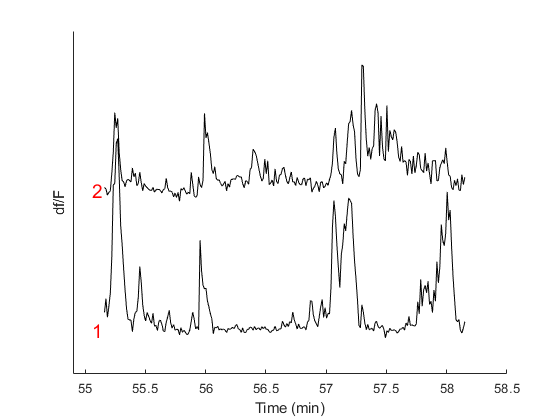

basepath = 'G:\sleep_wake_recordings\4621\JR_21_12_10_confon_GCaMP_4621\JR_21_12_10_confon_GCaMP_4621_211210_152259';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4621\JR_21_12_10_confon_GCaMP_4621\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

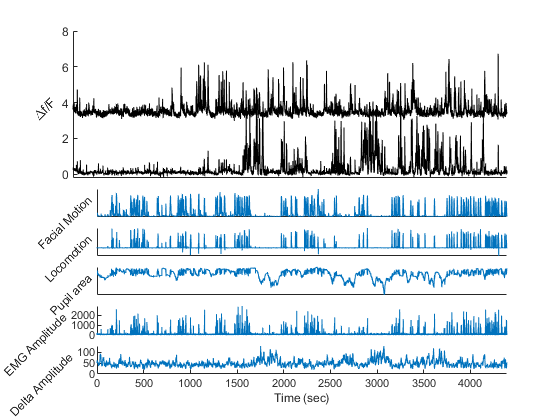


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

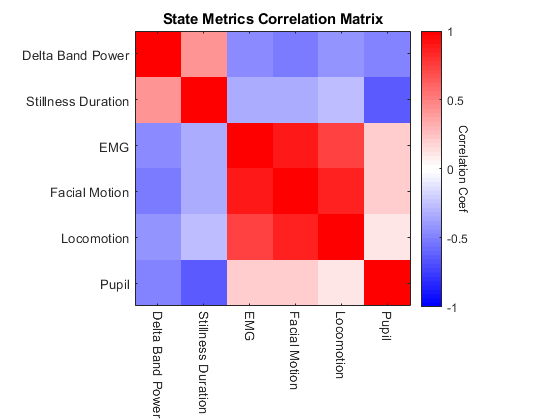

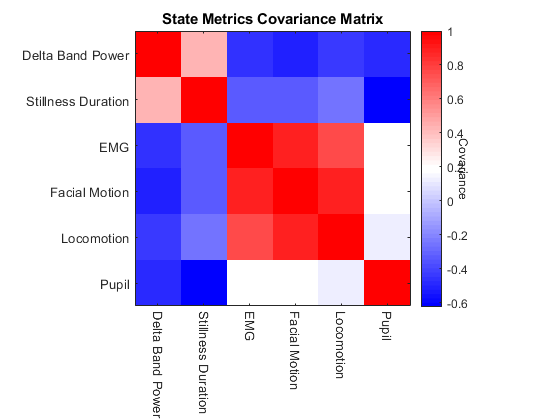

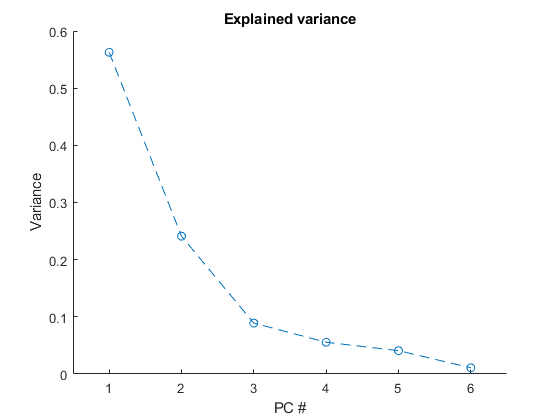

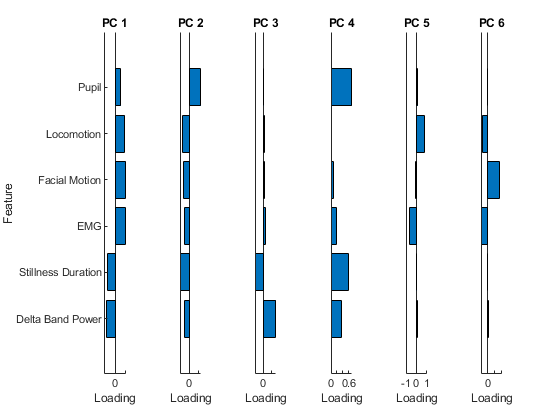

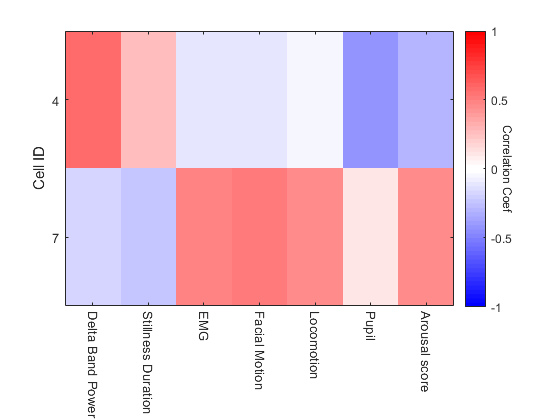

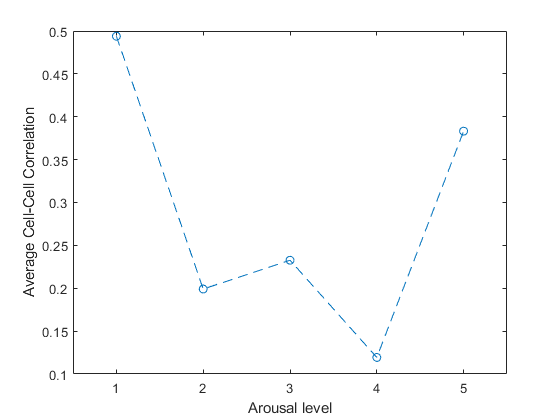


% Add cell IDs
imgStruct.cellIDs = Animal4621(3).cellIDs;
imgStruct.AnimalID = '4621';

% Analyze session
Animal4621(3).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4621 Day 4

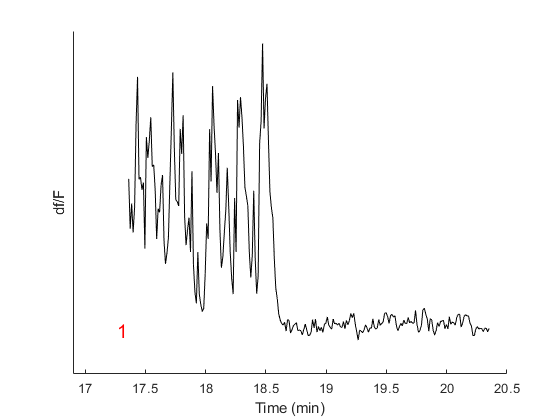

basepath = 'G:\sleep_wake_recordings\4621\JR_21_12_15_confon_GCaMP_4621\JR_21_12_15_confon_GCaMP_4621_211215_095340';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4621\JR_21_12_15_confon_GCaMP_4621\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

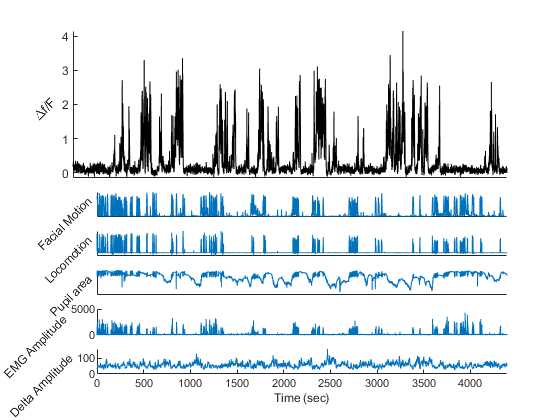


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

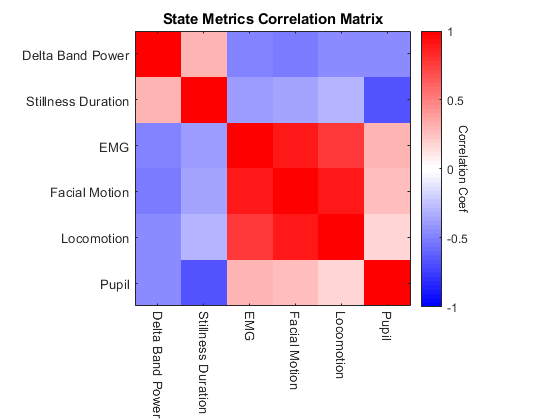

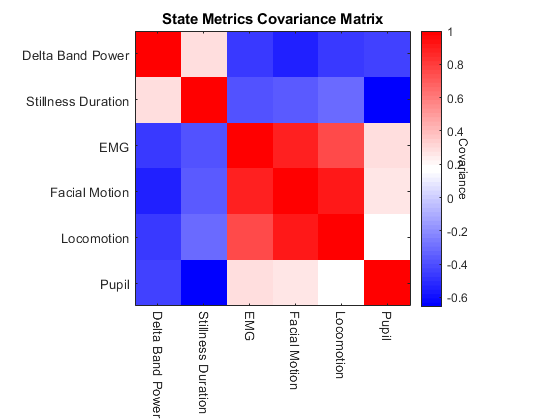

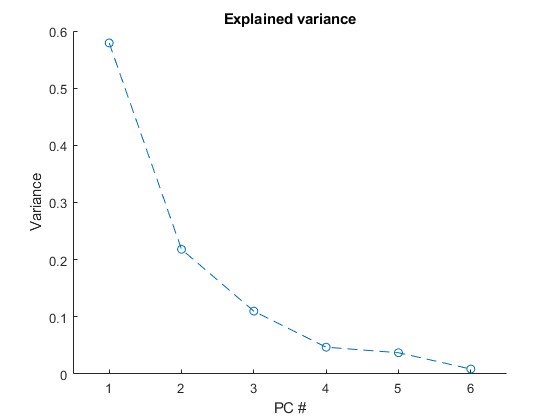

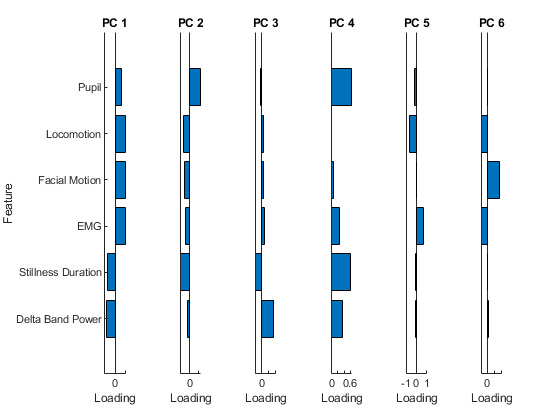

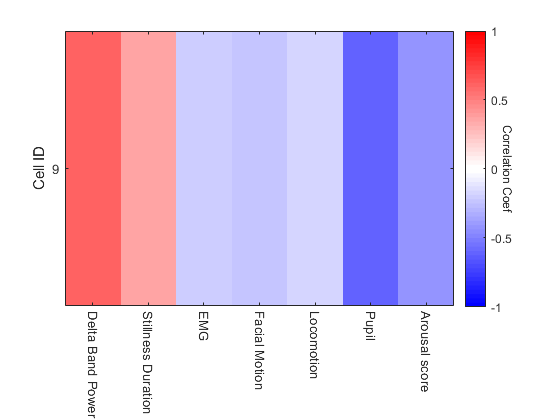


% Add cell IDs
imgStruct.cellIDs = Animal4621(4).cellIDs;
imgStruct.AnimalID = '4621';

% Analyze session
Animal4621(4).output = analyzeImagingWithoutSleep(imgStruct);

## Animal 4622

Single recording not of sufficient quality

## Animal 4627

Animal 4627 Day 1

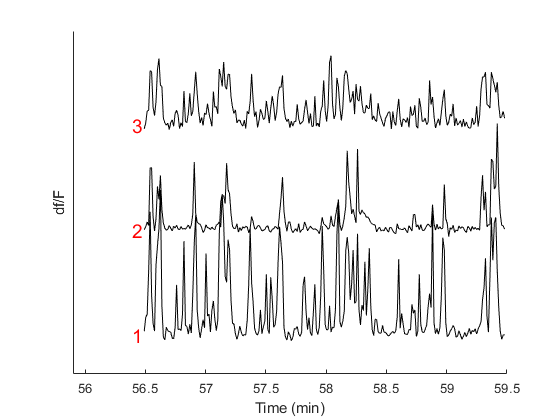

basepath = 'G:\sleep_wake_recordings\4627\JR_21_12_02_confon_GCaMP_4627\JR_21_12_02_confon_GCaMP_4627_211202_102220';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4627\JR_21_12_02_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

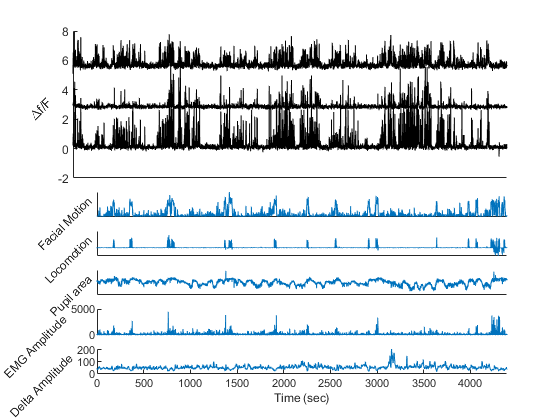


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

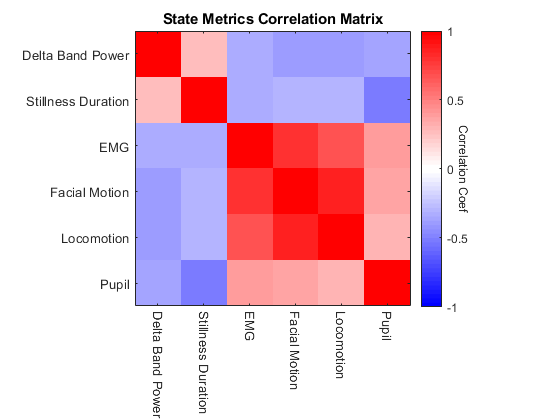

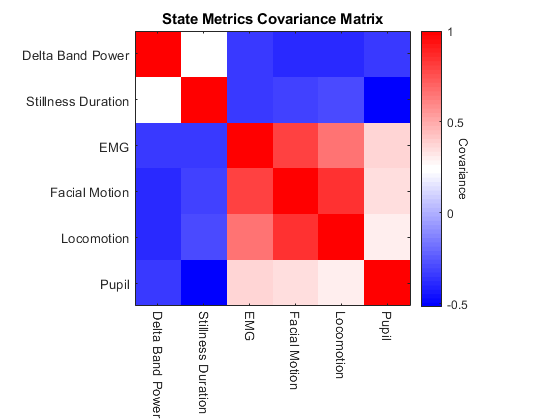

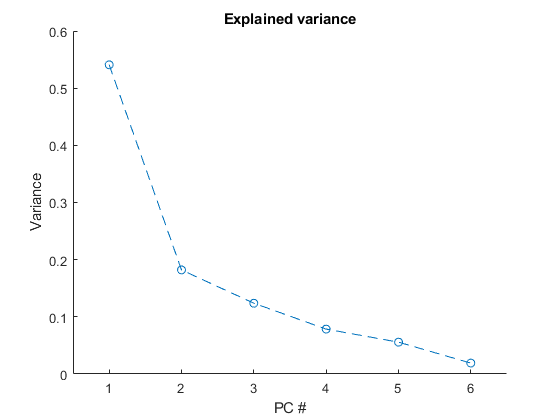

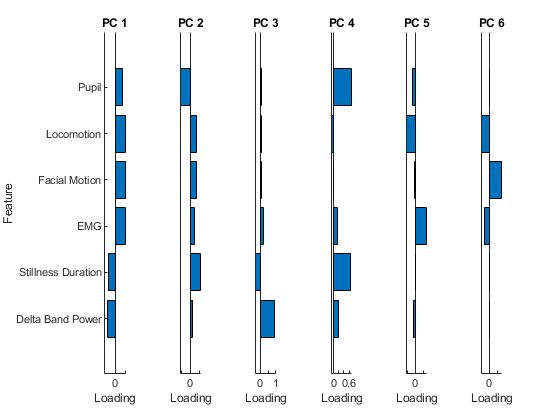

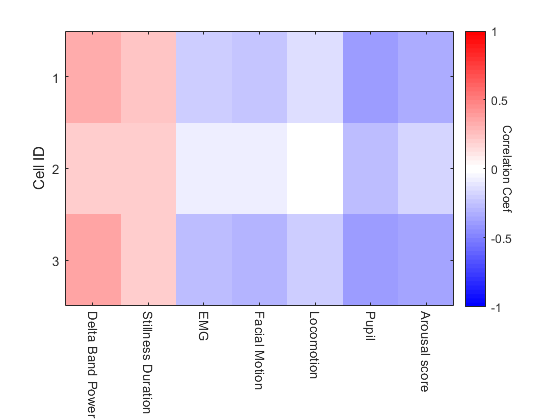

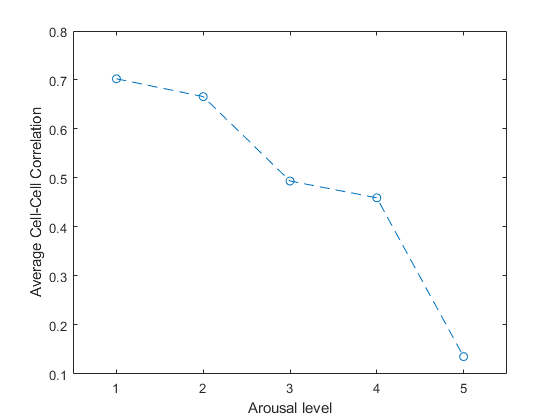


% Add cell IDs
imgStruct.cellIDs = Animal4627(1).cellIDs;
imgStruct.AnimalID = '4627';

% Analyze session
Animal4627(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4627 Day 2

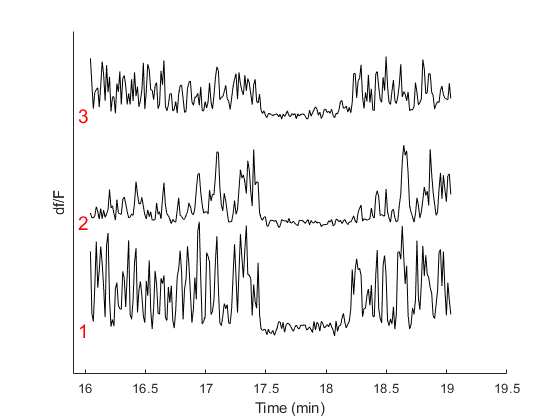

basepath = 'G:\sleep_wake_recordings\4627\JR_21_12_06_confon_GCaMP_4627\JR_21_12_06_confon_GCaMP_4627_211206_144336';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4627\JR_21_12_06_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

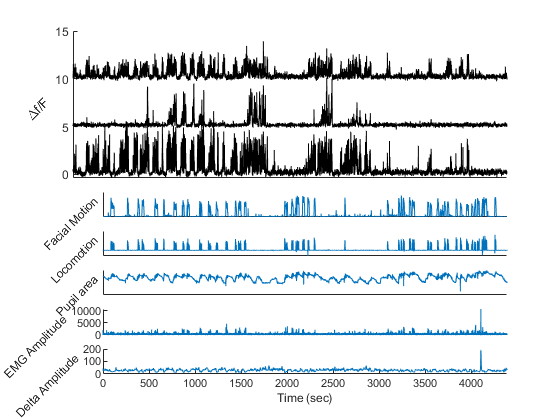


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

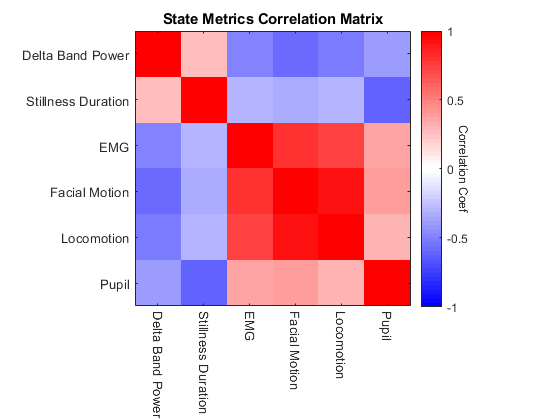

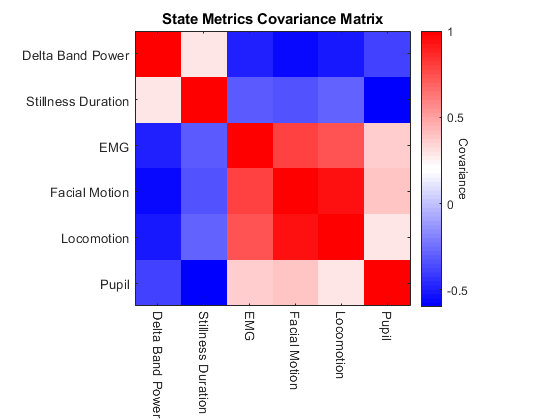

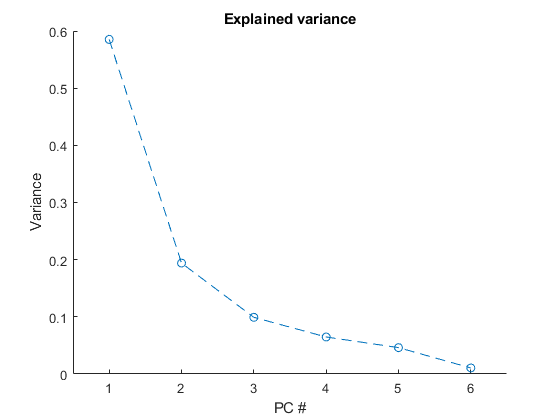

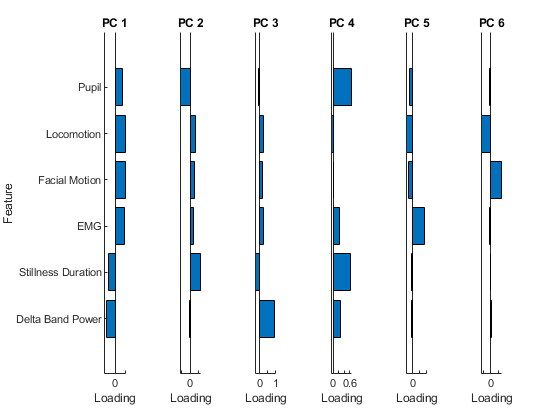

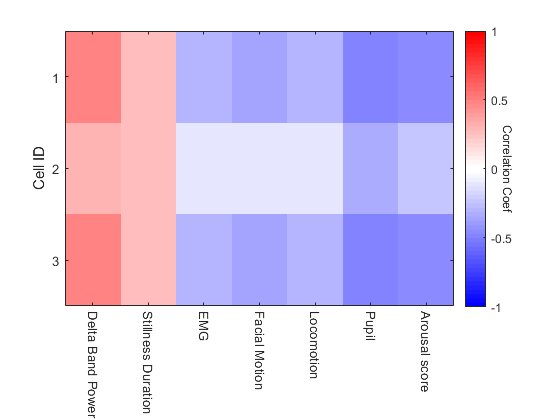

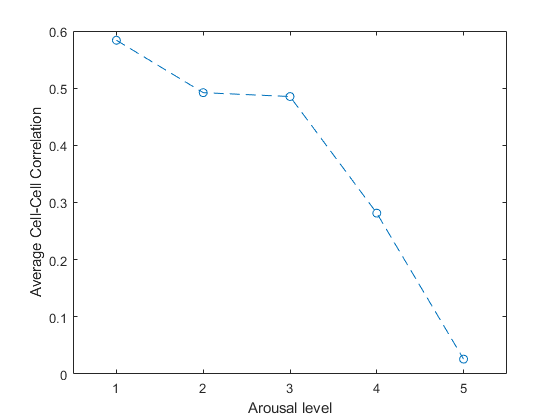


% Add cell IDs
imgStruct.cellIDs = Animal4627(2).cellIDs;
imgStruct.AnimalID = '4627';

% Analyze session
Animal4627(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4627 Day 3

This session had an issue with the camera data

% basepath = 'G:\sleep_wake_recordings\4627\JR_21_12_08_confon_GCaMP_4627\JR_21_12_08_confon_GCaMP_4627_211208_161954';
% imgpath = 'G:\sleep_wake_recordings\4627\JR_21_12_08_confon_GCaMP_4627\field1';
%
% s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
% imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
% imgStruct = alignImagingData(imgStruct,basepath,10,ops);
%
% figure
% plotImagingWithState(imgStruct);
%
% Animal4627(3).stats = cellStats(imgStruct, imgpath, s2pOut);

Animal 4627 Day 4

This session has an issue with the z plane changing

% basepath = 'G:\sleep_wake_recordings\4627\JR_21_12_14_confon_GCaMP_4627\JR_21_12_14_confon_GCaMP_4627_211214_104506';
% imgpath = 'G:\sleep_wake_recordings\4627\JR_21_12_14_confon_GCaMP_4627\field1';
%
% s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
% imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
% imgStruct = alignImagingData(imgStruct,basepath,10,ops);
%
% imgStruct.deltaF.time = imgStruct.deltaF.time(1:37051);
%
% figure
% plotImagingWithState(imgStruct);
%
% Animal4627(4).stats = cellStats(imgStruct, imgpath, s2pOut);

Animal 4627 Day 5 sleep

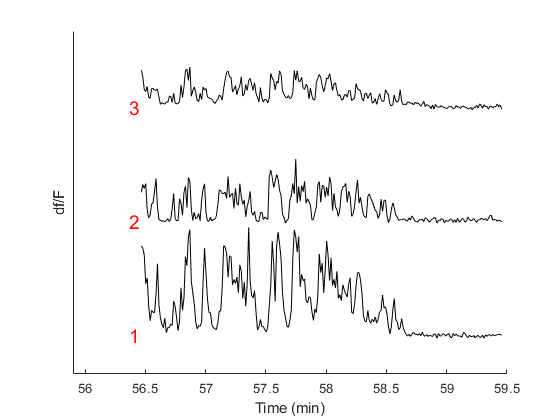

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_09_confon_GCaMP_4627\JR_22_05_09_confon_GCaMP_4627_220509_154655';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_05_09_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

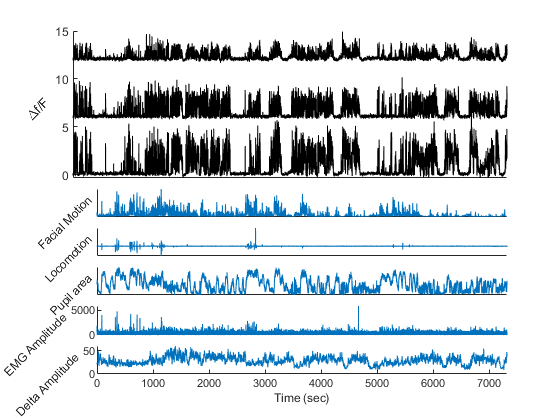


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

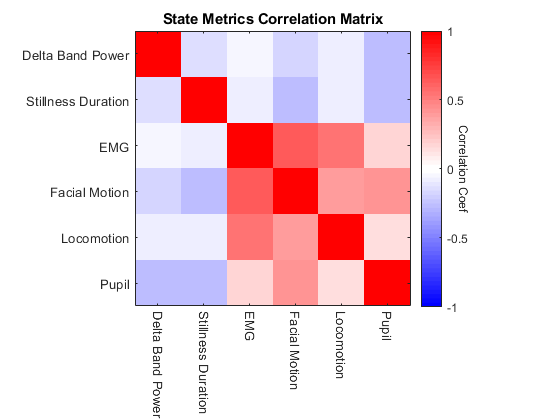

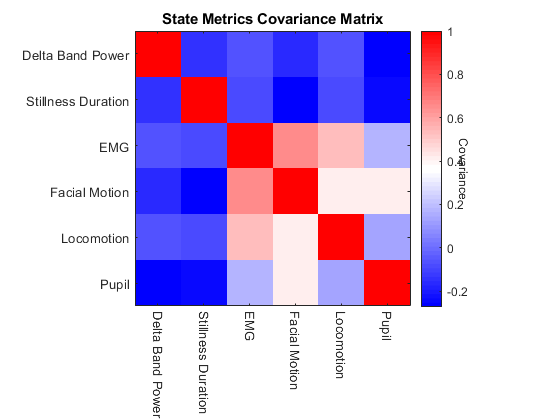

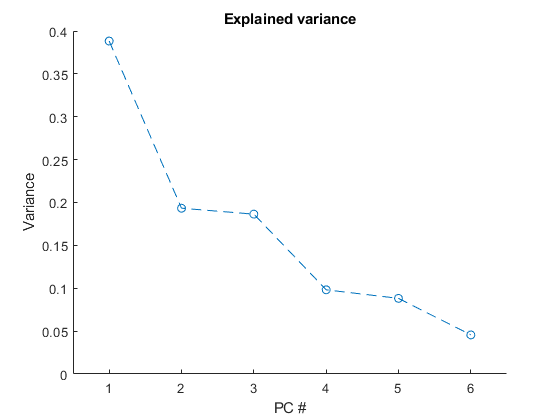

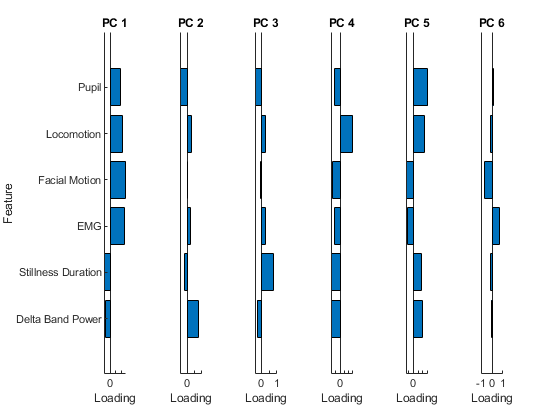

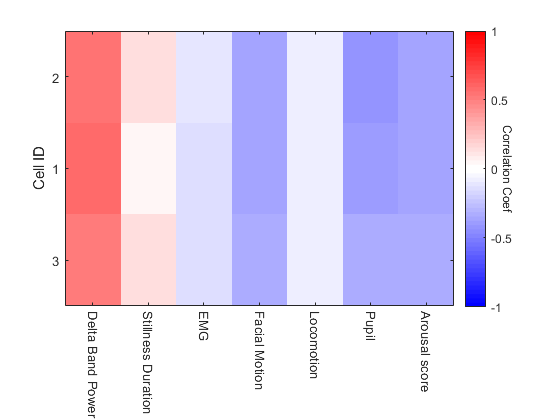

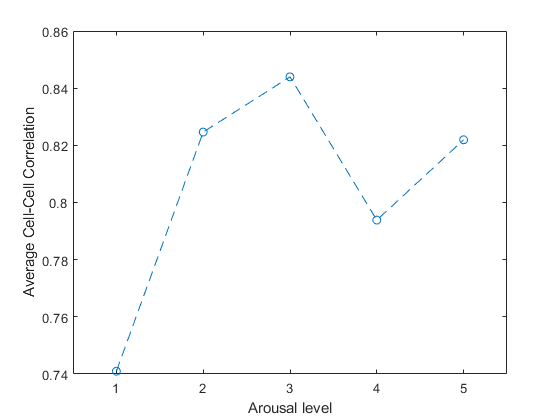


% Add cell IDs
imgStruct.cellIDs = Animal4627_sleep(1).cellIDs;
imgStruct.AnimalID = '4627';

% Analyze session
Animal4627(3).output = analyzeImagingWithoutSleep(imgStruct);

Animal4627(3).cellIDs = imgStruct.cellIDs;

Animal 4627 Day 6 sleep

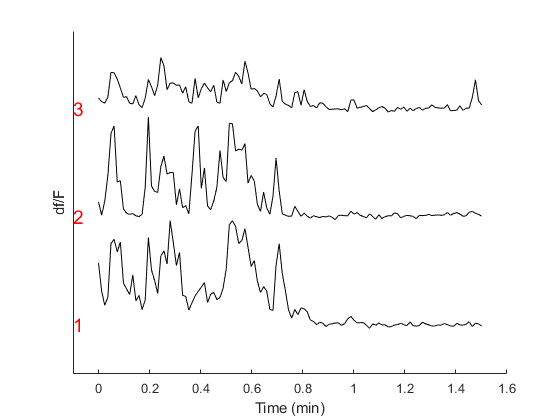

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_07_12_confon_GCaMP_4627\JR_22_07_12_confon_GCaMP_4627_220712_145339';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_07_12_confon_GCaMP_4627\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,10,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

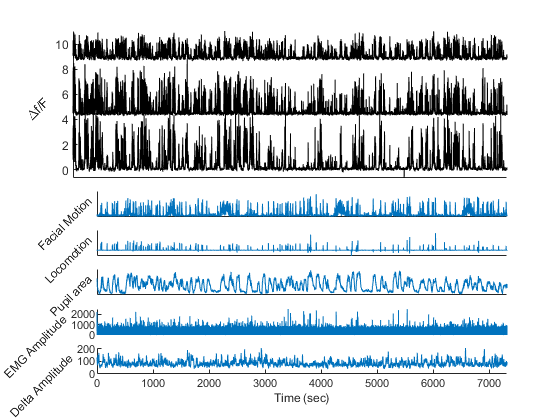


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

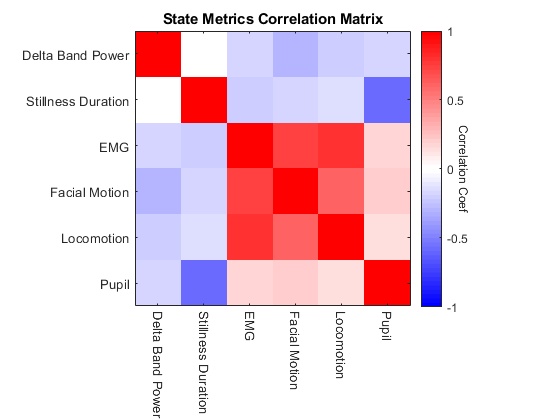

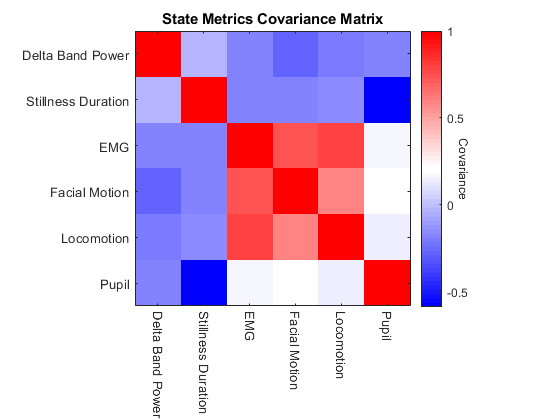

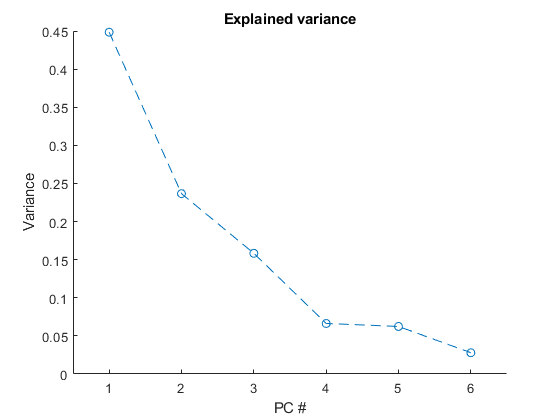

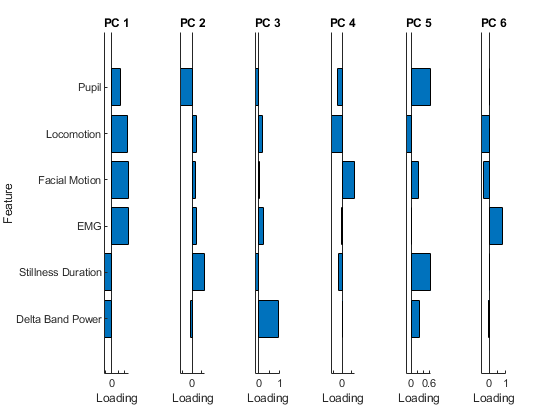

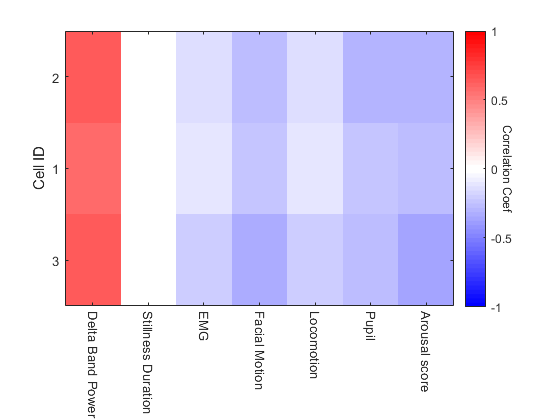

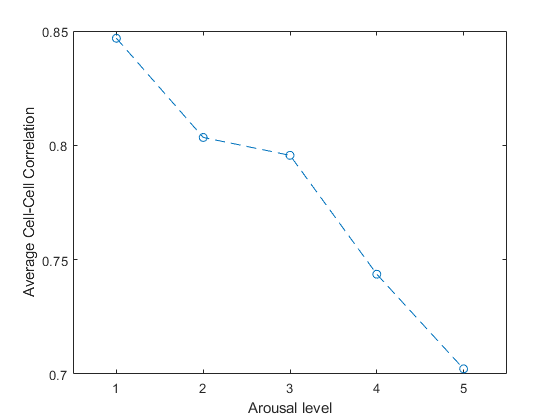


% Add cell IDs
imgStruct.cellIDs = Animal4627_sleep(2).cellIDs;
imgStruct.AnimalID = '4627';

% Analyze session
Animal4627(4).output = analyzeImagingWithoutSleep(imgStruct);

Animal4627(4).cellIDs = imgStruct.cellIDs;


## Animal 4632

Animal 4632 Day 1

basepath = 'G:\sleep_wake_recordings\4632\JR_21_12_06_confon_GCaMP_4632\JR_21_12_06_confon_GCaMP_4632_211206_121708';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4632\JR_21_12_06_confon_GCaMP_4632\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4632(1).cellIDs;
imgStruct.AnimalID = '4632';

% Analyze session
Animal4632(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4632 Day 2

basepath = 'G:\sleep_wake_recordings\4632\JR_21_12_08_confon_GCaMP_4632\JR_21_12_08_confon_GCaMP_4632_211208_123031';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4632\JR_21_12_08_confon_GCaMP_4632\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4632(2).cellIDs([1,2,3,5]);
imgStruct.AnimalID = '4632';

% Analyze session
Animal4632(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4632 Day 3

basepath = 'G:\sleep_wake_recordings\4632\JR_21_12_13_confon_GCaMP_4632\JR_21_12_13_confon_GCaMP_4632_211213_133501';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4632\JR_21_12_13_confon_GCaMP_4632\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4632(3).cellIDs;
imgStruct.AnimalID = '4632';

% Analyze session
Animal4632(3).output = analyzeImagingWithoutSleep(imgStruct);


Animal 4632 Day 4

basepath = 'G:\sleep_wake_recordings\4632\JR_21_12_15_confon_GCaMP_4632\JR_21_12_15_confon_GCaMP_4632_211215_155245';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4632\JR_21_12_15_confon_GCaMP_4632\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4632(4).cellIDs;
imgStruct.AnimalID = '4632';

% Analyze session
Animal4632(4).output = analyzeImagingWithoutSleep(imgStruct);

## Animal 4633

Animal 4633 Day 1

basepath = 'G:\sleep_wake_recordings\4633\JR_21_12_08_confon_GCaMP_4633\JR_21_12_08_confon_GCaMP_4633_211208_144106';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4633\JR_21_12_08_confon_GCaMP_4633\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4633(1).cellIDs;
imgStruct.AnimalID = '4633';

% Analyze session
Animal4633(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4633 Day 2

basepath = 'G:\sleep_wake_recordings\4633\JR_21_12_13_confon_GCaMP_4633\JR_21_12_13_confon_GCaMP_4633_211213_152325';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4633\JR_21_12_13_confon_GCaMP_4633\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4633(2).cellIDs;
imgStruct.AnimalID = '4633';

% Analyze session
Animal4633(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4633 Day 3

basepath = 'G:\sleep_wake_recordings\4633\JR_21_12_15_confon_GCaMP_4633\JR_21_12_15_confon_GCaMP_4633_211215_172953';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4633\JR_21_12_15_confon_GCaMP_4633\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

imgStruct.deltaF.time = imgStruct.deltaF.time(1:6000);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4633(3).cellIDs;
imgStruct.AnimalID = '4633';

% Analyze session
Animal4633(3).output = analyzeImagingWithoutSleep(imgStruct);

## Animal 4634

Animal 4634 Day 1

basepath = 'G:\sleep_wake_recordings\4634\JR_21_12_03_confon_GCaMP_4634\JR_21_12_03_confon_GCaMP_4634_211203_154542';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4634\JR_21_12_03_confon_GCaMP_4634\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4634(1).cellIDs;
imgStruct.AnimalID = '4634';

% Analyze session
Animal4634(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4634 Day 2

basepath = 'G:\sleep_wake_recordings\4634\JR_21_12_08_confon_GCaMP_4634\JR_21_12_08_confon_GCaMP_4634_211208_103657';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4634\JR_21_12_08_confon_GCaMP_4634\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4634(2).cellIDs;
imgStruct.AnimalID = '4634';

% Analyze session
Animal4634(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4634 Day 3

basepath = 'G:\sleep_wake_recordings\4634\JR_21_12_13_confon_GCaMP_4634\JR_21_12_13_confon_GCaMP_4634_211213_113139';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4634\JR_21_12_13_confon_GCaMP_4634\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4634(3).cellIDs;
imgStruct.AnimalID = '4634';

% Analyze session
Animal4634(3).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4634 Day 4

basepath = 'G:\sleep_wake_recordings\4634\JR_21_12_15_confon_GCaMP_4634\JR_21_12_15_confon_GCaMP_4634_211215_141822';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4634\JR_21_12_15_confon_GCaMP_4634\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4634(4).cellIDs;
imgStruct.AnimalID = '4634';

% Analyze session
Animal4634(4).output = analyzeImagingWithoutSleep(imgStruct);

## Animal 4637

Animal 4637 Day 1

basepath = 'G:\sleep_wake_recordings\4637\JR_21_12_02_confon_GCaMP_4637\JR_21_12_02_confon_GCaMP_4637_211202_115652';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4637\JR_21_12_02_confon_GCaMP_4637\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4637(1).cellIDs;
imgStruct.AnimalID = '4637';

% Analyze session
Animal4637(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4637 Day 2

basepath = 'G:\sleep_wake_recordings\4637\JR_21_12_06_confon_GCaMP_4637\JR_21_12_06_confon_GCaMP_4637_211206_163734';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4637\JR_21_12_06_confon_GCaMP_4637\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4637(2).cellIDs;
imgStruct.AnimalID = '4637';

% Analyze session
Animal4637(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4637 Day 3

basepath = 'G:\sleep_wake_recordings\4637\JR_21_12_10_confon_GCaMP_4637\JR_21_12_10_confon_GCaMP_4637_211210_112913';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4637\JR_21_12_10_confon_GCaMP_4637\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4637(3).cellIDs;
imgStruct.AnimalID = '4637';

% Analyze session
Animal4637(3).output = analyzeImagingWithoutSleep(imgStruct);

Animal 4637 Day 4

basepath = 'G:\sleep_wake_recordings\4637\JR_21_12_14_confon_GCaMP_4637\JR_21_12_14_confon_GCaMP_4637_211214_125741';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'G:\sleep_wake_recordings\4637\JR_21_12_14_confon_GCaMP_4637\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

imgStruct.deltaF.time = imgStruct.deltaF.time(1:6287);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4637(4).cellIDs;
imgStruct.AnimalID = '4637';

% Analyze session
Animal4637(4).output = analyzeImagingWithoutSleep(imgStruct);

## Animal 3300

Animal 3300 Day 1

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_03_confon_GCaMP_animal_1\JR_22_08_03_confon_GCaMP_animal_1_220803_144226';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_03_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal3300_sleep(1).cellIDs;
imgStruct.AnimalID = '3300';

% Analyze session
Animal3300(1).output = analyzeImagingWithoutSleep(imgStruct);
Animal3300(1).cellIDs = imgStruct.cellIDs;

Animal 3300 Day 2

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_05_confon_GCaMP_animal_1\JR_22_08_05_confon_GCaMP_animal_1_220805_151711';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_05_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal3300_sleep(2).cellIDs;
imgStruct.AnimalID = '3300';

% Analyze session
Animal3300(2).output = analyzeImagingWithoutSleep(imgStruct);
Animal3300(2).cellIDs = imgStruct.cellIDs;

Animal 3300 Day 3

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_09_confon_GCaMP_animal_1\JR_22_08_09_confon_GCaMP_animal_1_220809_140641';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_09_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal3300_sleep(3).cellIDs;
imgStruct.AnimalID = '3300';

% Analyze session
Animal3300(3).output = analyzeImagingWithoutSleep(imgStruct);
Animal3300(3).cellIDs = imgStruct.cellIDs;

Animal 3300 Day 4

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_12_confon_GCaMP_animal_1\JR_22_08_12_confon_GCaMP_animal_1_220812_160050';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_08_12_confon_GCaMP_animal_1\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal3300_sleep(4).cellIDs;
imgStruct.AnimalID = '3300';

% Analyze session
Animal3300(4).output = analyzeImagingWithoutSleep(imgStruct);
Animal3300(4).cellIDs = imgStruct.cellIDs;

## Animal 5646

Animal 5646 Day 1

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_10_13_confon_GCaMP_animal_5646\JR_22_10_13_confon_GCaMP_animal_5646_221013_152101';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\JR_22_10_13_confon_GCaMP_animal_5646\field1';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);
imgStruct = alignImagingData(imgStruct,basepath,10,ops);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:6,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal5646_sleep(1).cellIDs;
imgStruct.AnimalID = '5646';

% Analyze session
Animal5646(1).output = analyzeImagingWithoutSleep(imgStruct);
Animal5646(1).cellIDs = imgStruct.cellIDs;

## Animal 4094

Animal 4094 Day 1

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\4094\09202022_SOMnNOS\Test_Vehicle_220920_154142';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\4094\09202022_SOMnNOS\field1';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(1:14,'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data; % - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels', 5);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal4094_sleep(1).cellIDs;
imgStruct.AnimalID = '4094';

% Analyze session
Animal4094(1).output = analyzeImagingWithoutSleep(imgStruct);
Animal4094(1).cellIDs = imgStruct.cellIDs;

## Animal 5628

Animal 5628 Day 1

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\11232022_SOMnNOS\5628_AFDX_221123_152657';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\11232022_SOMnNOS\5628_AFDX';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

imgStruct.AlignedData.faceMotion.data(500) = mean(imgStruct.AlignedData.faceMotion.data); % removing outlier

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([0:2 12:15],'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data; % - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal5628_sleep(1).cellIDs;
imgStruct.AnimalID = '5628';

% Analyze session
Animal5628(1).output = analyzeImagingWithoutSleep(imgStruct);
Animal5628(1).cellIDs = imgStruct.cellIDs;

Animal 5628 Day 2

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12092022_SOMnNOS\Pre_injection\AFDX1mM_221209_125812';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12092022_SOMnNOS\Pre_injection\preAFDX';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([1:2 12:15],'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data; % - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal5628_sleep(2).cellIDs;
imgStruct.AnimalID = '5628';

% Analyze session
Animal5628(2).output = analyzeImagingWithoutSleep(imgStruct);
Animal5628(2).cellIDs = imgStruct.cellIDs;

Animal 5628 Day 3

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12212022_SOMnNOS\AFDX1mM_221221_143557';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12212022_SOMnNOS\AFDX_tif';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([1:2 12:15],'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal5628_sleep(3).cellIDs;
imgStruct.AnimalID = '5628';

% Analyze session
Animal5628(3).output = analyzeImagingWithoutSleep(imgStruct);
Animal5628(3).cellIDs = imgStruct.cellIDs;

Animal 5628 Day 4

basepath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12222022_SOMnNOS\AFDX1mM_221222_150023';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\jacob\Data2_archive\SST_nNOS_sleep_imaging\5628\12222022_SOMnNOS\AFDX_tif';

imgStruct = SSTnNOS.geoffreyDataImportWrapper(basepath);

% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP([1:2 12:15],'basepath',basepath);
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

% Add cell IDs
imgStruct.cellIDs = Animal5628_sleep(4).cellIDs;
imgStruct.AnimalID = '5628';

% Analyze session
Animal5628(4).output = analyzeImagingWithoutSleep(imgStruct);
Animal5628(4).cellIDs = imgStruct.cellIDs;


## New chodl imaging data from 2024 below

ops.cameraTriggerChan = 10;
ops.treadmillChan = 11;
ops.overwrite = false;


## Animal 7776

Animal 7776 Day 1

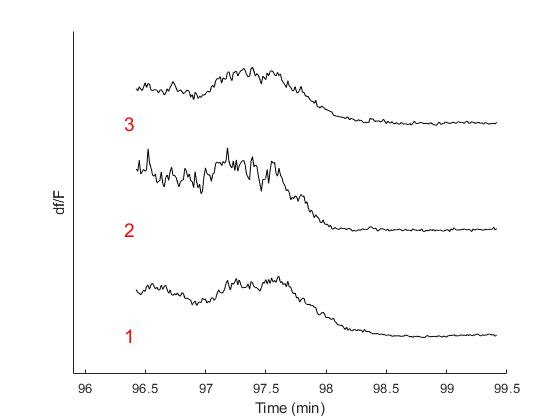

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240416_150720';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240416_150720\Imaging_04_16_2024_85um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

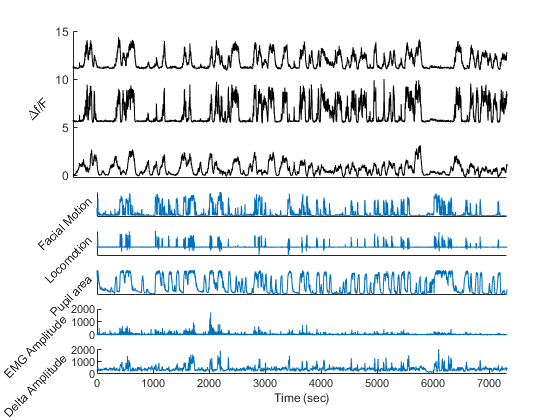


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

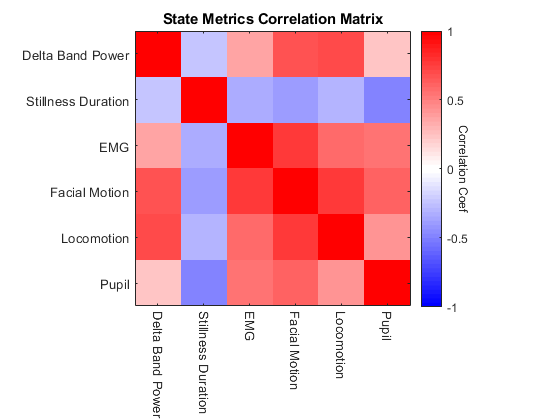

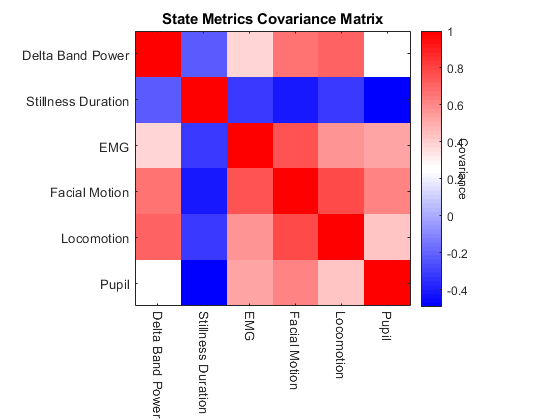

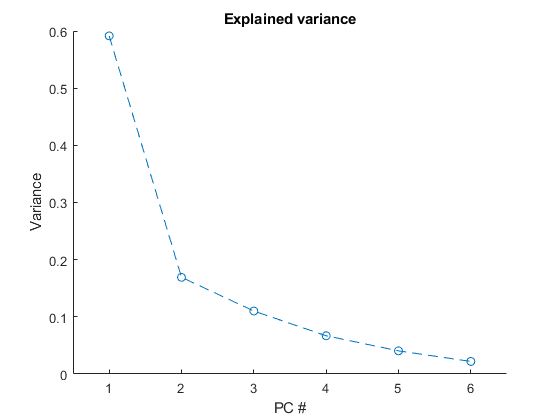

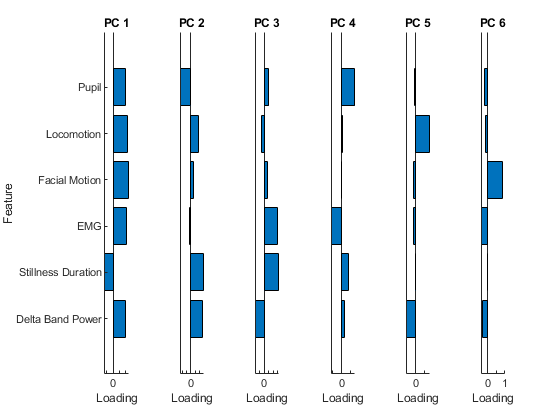

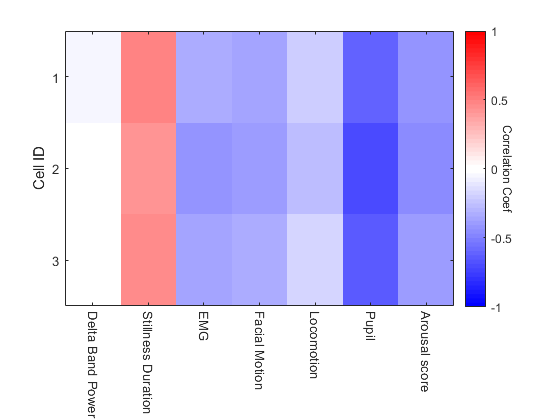

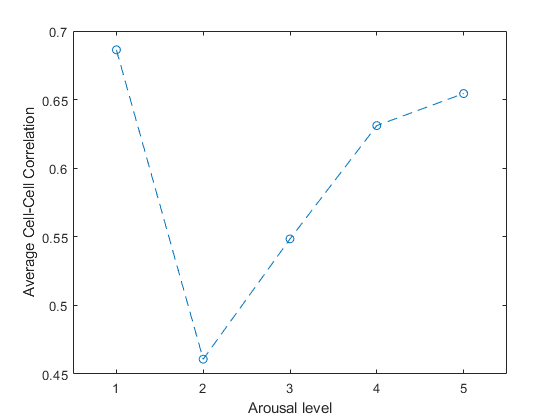


% Add cell IDs and Animal ID
imgStruct.cellIDs = 1:3;
imgStruct.AnimalID = '7776';

% Analyze session
Animal7776(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal7776(1).cellIDs = imgStruct.cellIDs;

Animal 7776 Day 2

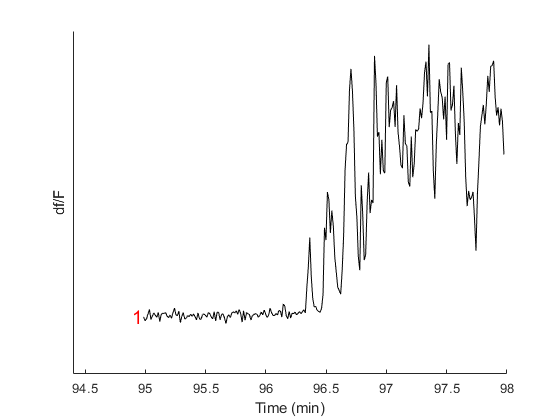

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240417_114748';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240417_114748\Imaging_04_17_2024_200um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

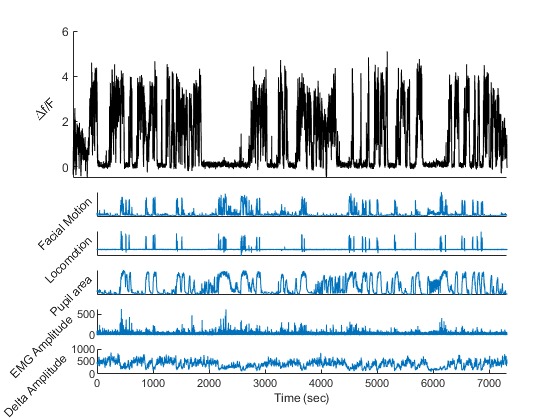


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

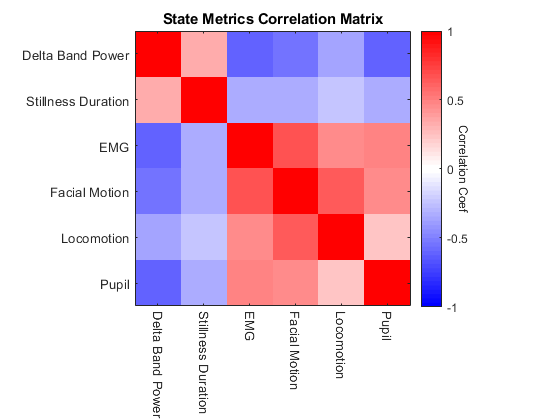

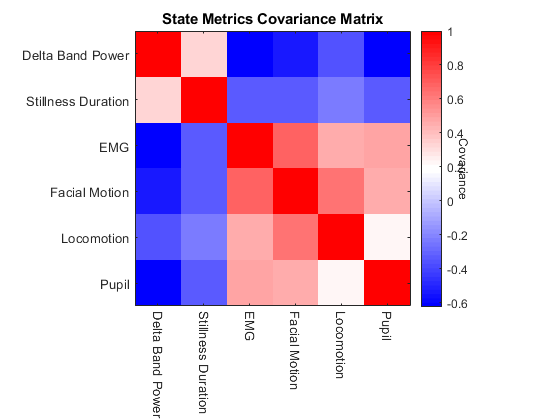

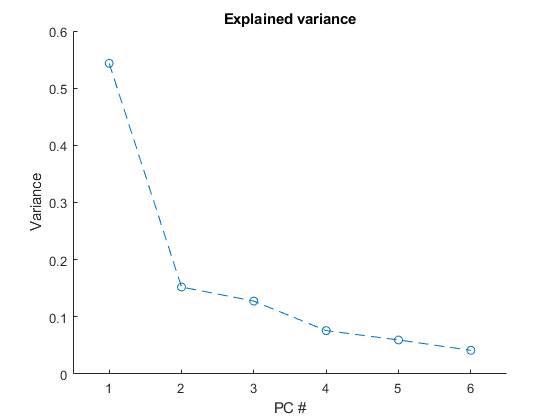

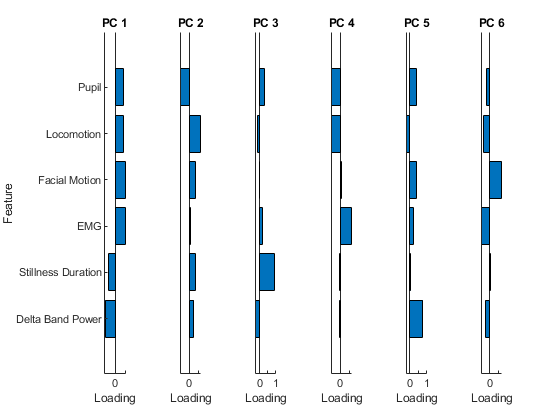

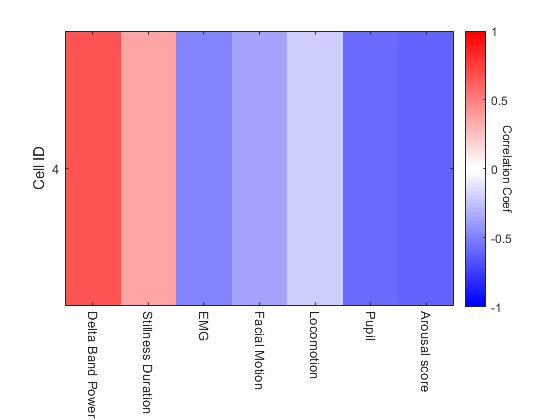


% Add cell IDs and Animal ID
imgStruct.cellIDs = 4;
imgStruct.AnimalID = '7776';

% Analyze session
Animal7776(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal7776(2).cellIDs = imgStruct.cellIDs;

Animal 7776 Day 3

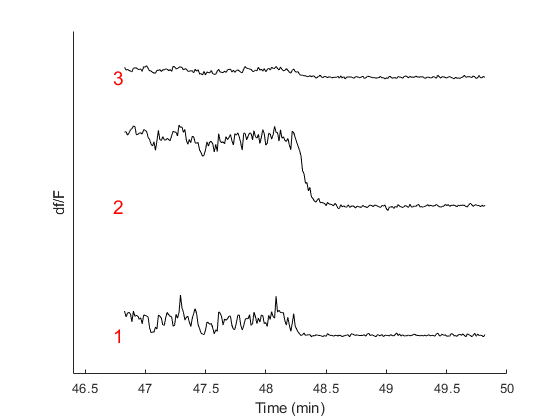

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240418_115444';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240418_115444\Imaging_04_18_2024_15um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

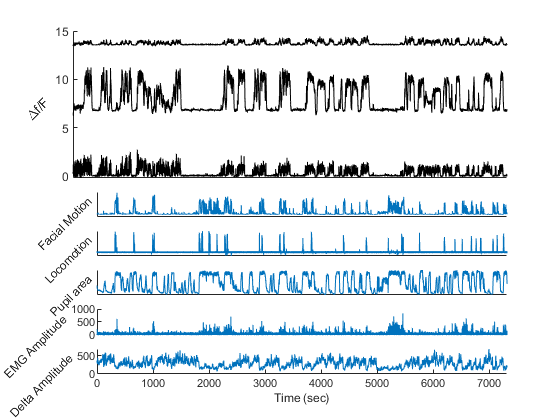


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

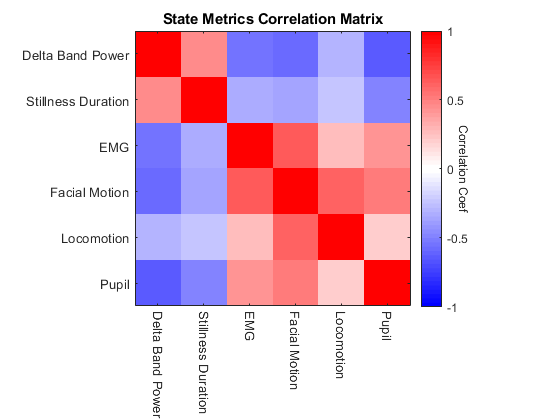

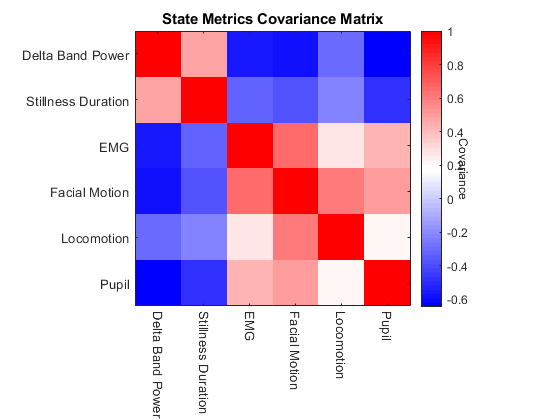

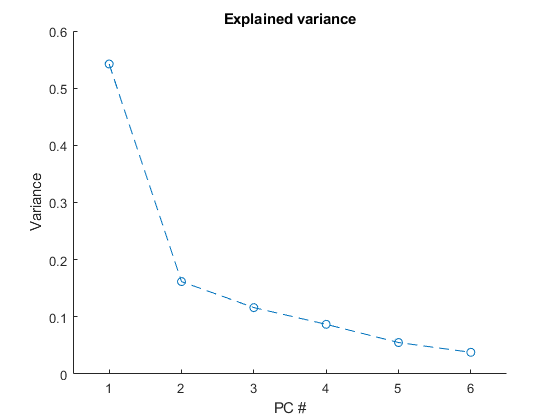

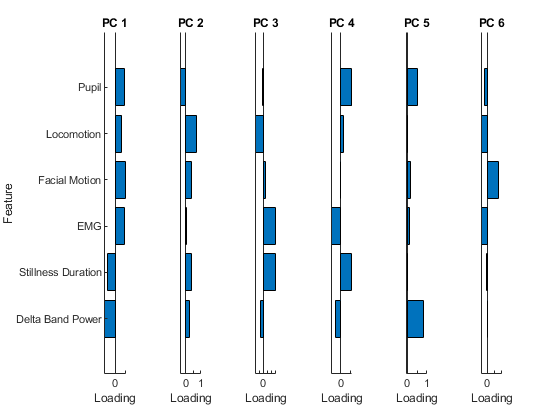

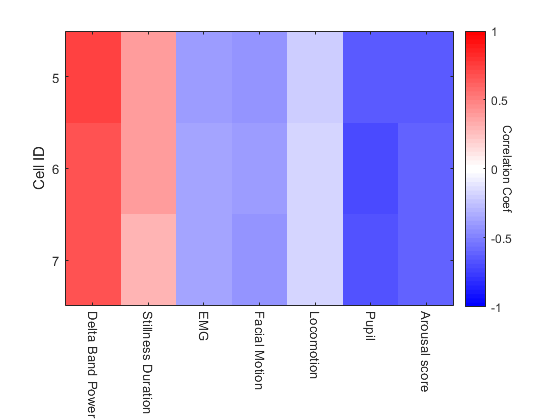

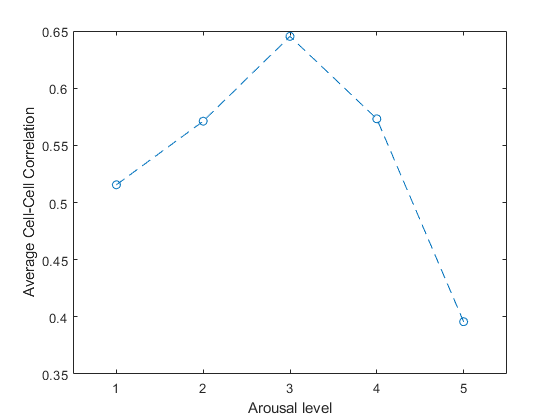


% Add cell IDs and Animal ID
imgStruct.cellIDs = 5:7;
imgStruct.AnimalID = '7776';

% Analyze session
Animal7776(3).output = analyzeImagingWithoutSleep(imgStruct);

Animal7776(3).cellIDs = imgStruct.cellIDs;

Animal 7776 Day 4

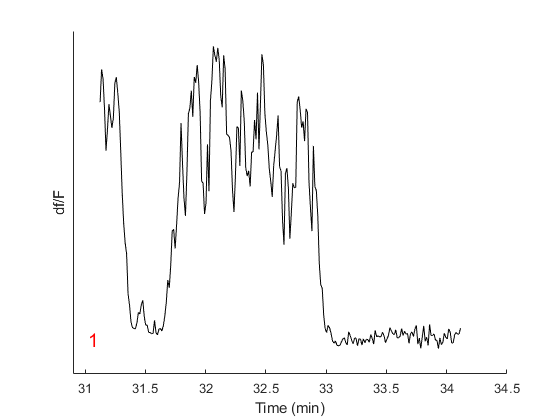

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240419_155705';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7776\7776_240419_155705\Imaging_04_19_2024_70um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

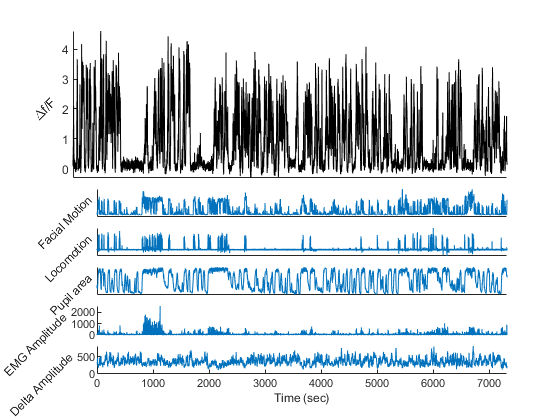


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

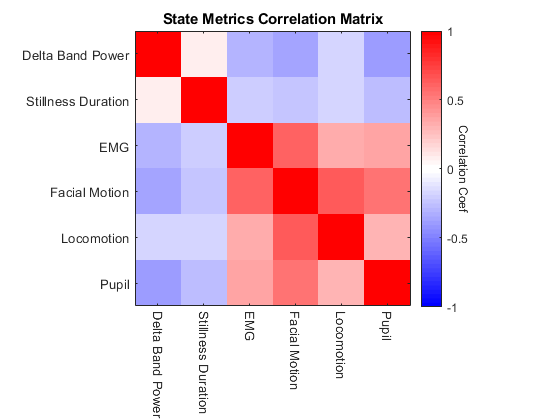

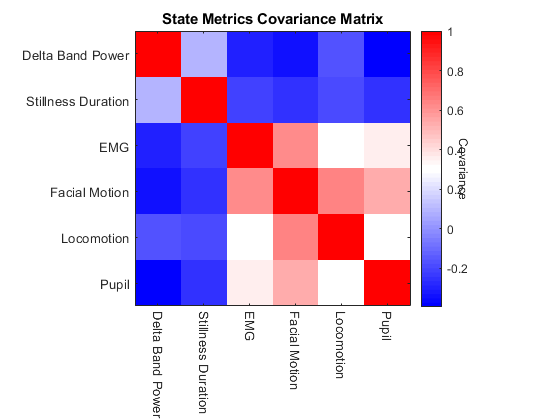

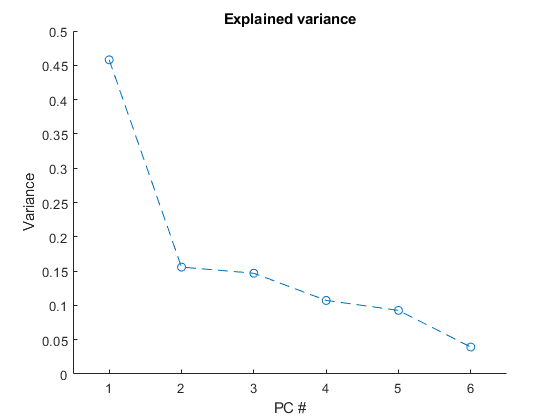

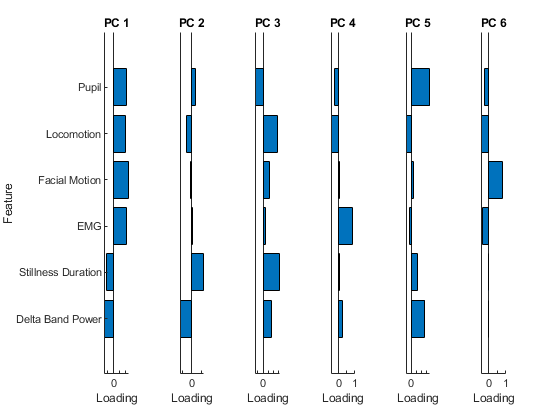

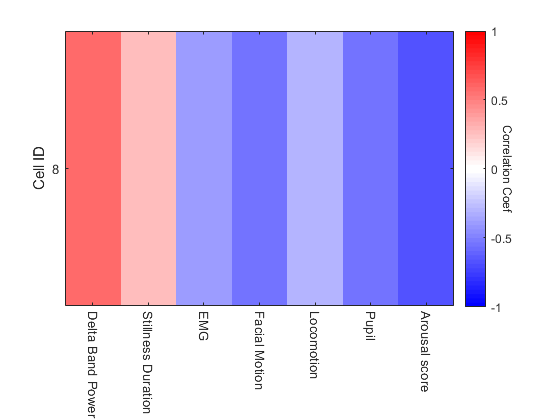


% Add cell IDs and Animal ID
imgStruct.cellIDs = 8;
imgStruct.AnimalID = '7776';

% Analyze session
Animal7776(4).output = analyzeImagingWithoutSleep(imgStruct);

Animal7776(4).cellIDs = imgStruct.cellIDs;

## Animal 7777

Animal 7777 Day 1

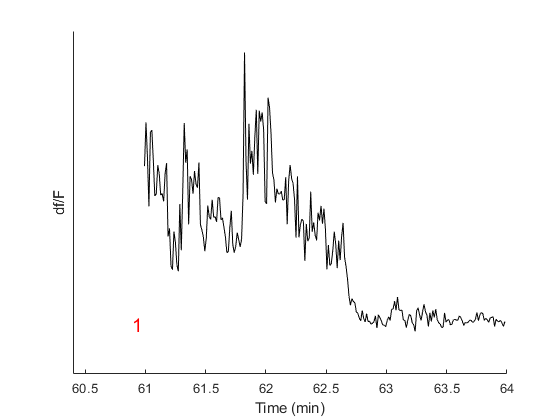

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240501_160828';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240501_160828\05-01-2024-30um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

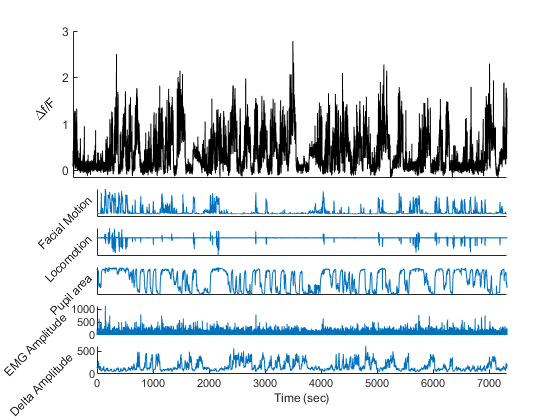


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

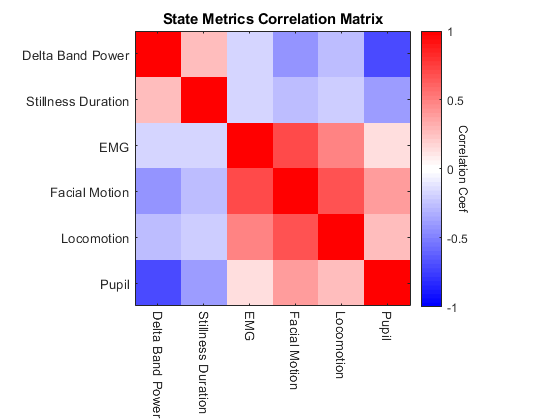

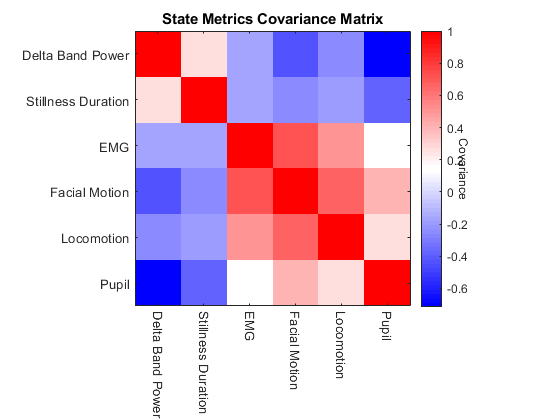

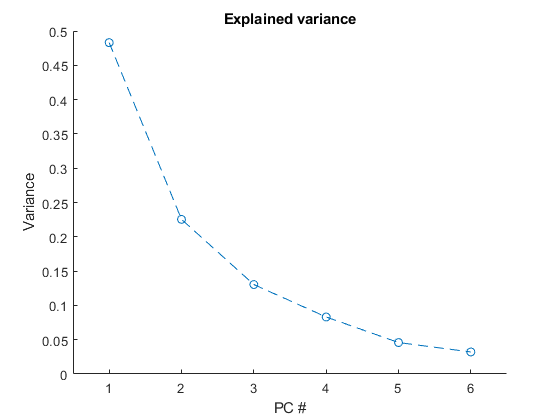

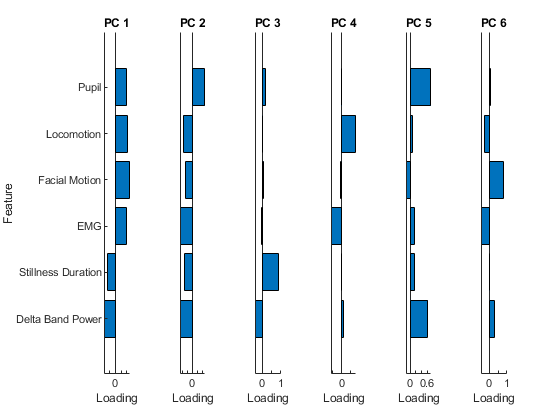

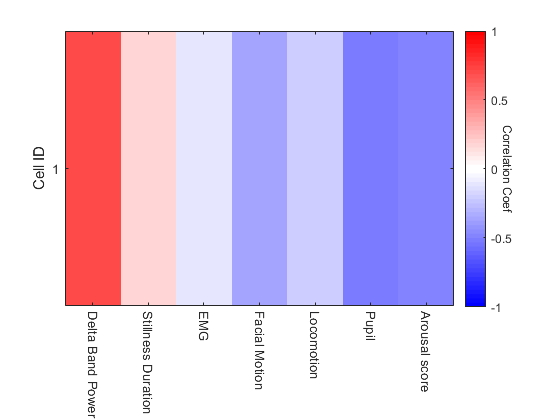


% Add cell IDs and Animal ID
imgStruct.cellIDs = 1;
imgStruct.AnimalID = '7777';

% Analyze session
Animal7777(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal7777(1).cellIDs = imgStruct.cellIDs;

Animal 7777 Day 2

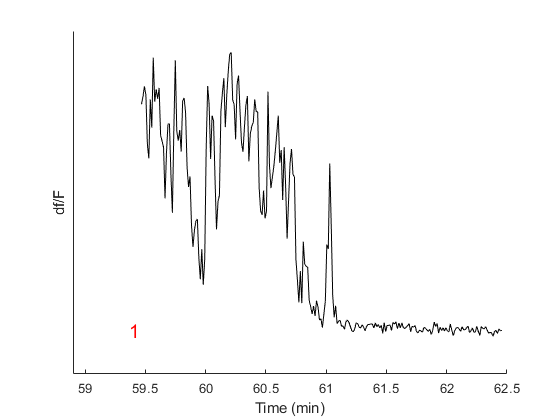

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240508_144803';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7777\7777_240508_144803\Imaging_05-08-2024-80um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);

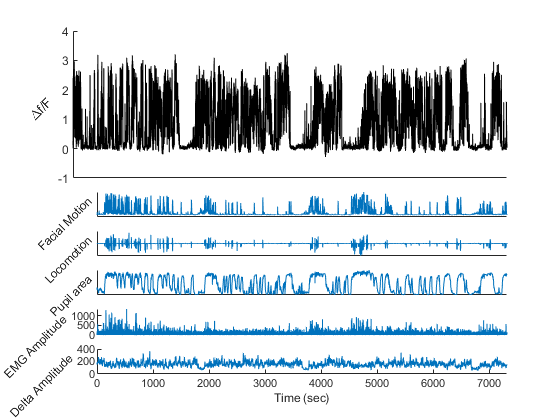


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);

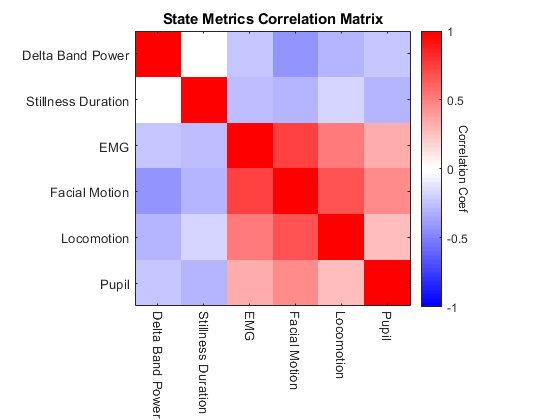

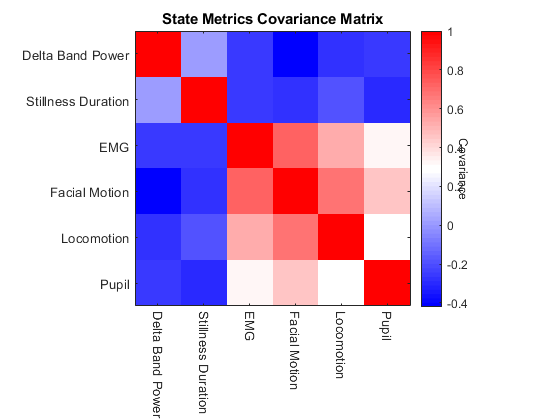

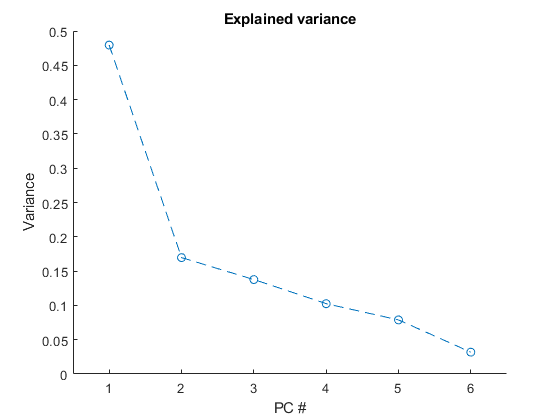

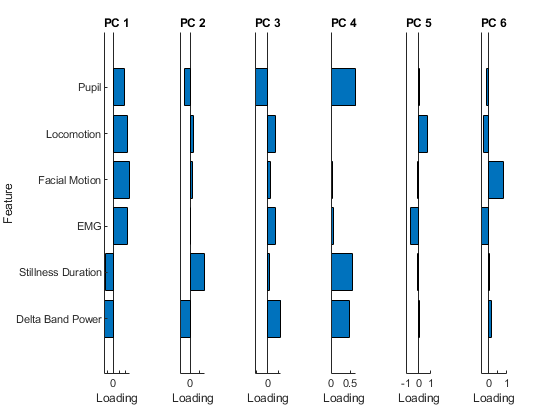

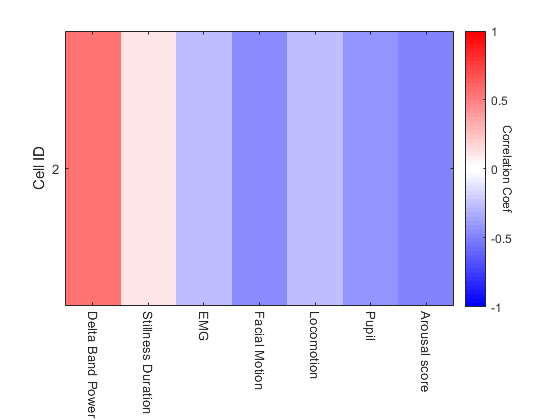


% Add cell IDs and Animal ID
imgStruct.cellIDs = 2;
imgStruct.AnimalID = '7777';

% Analyze session
Animal7777(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal7777(2).cellIDs = imgStruct.cellIDs;

## Animal 7992

Animal 7992 Day 1

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240416_120003';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240416_120003\Imaging_04_16_2024_70um_000';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);


% Add cell IDs and Animal ID
imgStruct.cellIDs = 1:4;
imgStruct.AnimalID = '7992';

% Analyze session
Animal7992(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal7992(1).cellIDs = imgStruct.cellIDs;

Animal 7992 Day 2

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240418_143030';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240418_143030\Imaging_04_18_2024_10um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);


% Add cell IDs and Animal ID
imgStruct.cellIDs = 5;
imgStruct.AnimalID = '7992';

% Analyze session
Animal7992(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal7992(2).cellIDs = imgStruct.cellIDs;

Animal 7992 Day 3

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240419_132238';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240419_132238\Imaging_04_19_2024_155um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);


% Add cell IDs and Animal ID
imgStruct.cellIDs = 6:8;
imgStruct.AnimalID = '7992';

% Analyze session
Animal7992(3).output = analyzeImagingWithoutSleep(imgStruct);

Animal7992(3).cellIDs = imgStruct.cellIDs;

Animal 7992 Day 4

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240422_124051';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7992\7992_240422_124051\Imaging_04_22_2024_140um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);


% Add cell IDs and Animal ID
imgStruct.cellIDs = 9;
imgStruct.AnimalID = '7992';

% Analyze session
Animal7992(4).output = analyzeImagingWithoutSleep(imgStruct);

Animal7992(4).cellIDs = imgStruct.cellIDs;

## Animal 7995

Animal 7995 Day 1

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240501_125221';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240501_125221\Imaging_05-01-2024-0um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);


% Add cell IDs and Animal ID
imgStruct.cellIDs = 1;
imgStruct.AnimalID = '7995';

% Analyze session
Animal7995(1).output = analyzeImagingWithoutSleep(imgStruct);

Animal7995(1).cellIDs = imgStruct.cellIDs;

Animal 7995 Day 2

basepath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240514_144726';
basename = bz_BasenameFromBasepath(basepath);
imgpath = 'X:\SharedData_JR_GT\2p_Imaging\Chodl_SST_Geoffrey\7995\7995_240514_144726\Imaging_05-14-2024-170um';

s2pOut = retrieveSuite2pOutput(imgpath + "\suite2p");
imgStruct = initializeImagingAnalysisStruct(s2pOut,1.366, ops1);

imgStruct = alignImagingData(imgStruct,basepath,9,ops);

Loading previously aligned imaging data...



% Load lfp and extract EMG and delta band power
lfp = bz_GetLFP(0:7,'basepath',basepath);

Loading Channels 0  1  2  3  4  5  6  7 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);
load(fullfile(basepath, basename + ".SleepState.states.mat"))
delta = bz_Filter(lfpReref,'passband',[0 4],'channels',SleepState.detectorinfo.detectionparms.SleepScoreMetrics.SWchanID);


EMG = getEMGfromLFP(lfp);

% Align EMG and Delta to imaging data
imgStruct.delta = delta;
imgStruct.delta.amp = movmedian(imgStruct.delta.amp,imgStruct.delta.samplingRate*7);
imgStruct.delta.timestamps = delta.timestamps - imgStruct.firstScopeFrameTime;
imgStruct.EMG = EMG;
imgStruct.EMG.timestamps = EMG.timestamps - imgStruct.firstScopeFrameTime;

figure
plotImagingWithState(imgStruct);


% Add cell IDs and Animal ID
imgStruct.cellIDs = 2;
imgStruct.AnimalID = '7995';

% Analyze session
Animal7995(2).output = analyzeImagingWithoutSleep(imgStruct);

Animal7995(2).cellIDs = imgStruct.cellIDs;

% Combine data across animals into table
animals = [Animal4612 Animal4621 Animal4627 Animal4632 Animal4633 Animal4634 Animal4637 Animal3300 Animal5646 Animal4094 Animal5628 ...
    Animal7776 Animal7777 Animal7992 Animal7995];

warning('off')
animalTables = combineAcrossAnimals(animals);
warning('on')

figure
plotting.cellStateCorr = cell2mat(animalTables.Cells.CellStateCorrelation);
[~, plotting.arrousalCorrSortedInds] = sort(animalTables.Cells.ArousalCorrelation);
imagesc(plotting.cellStateCorr(plotting.arrousalCorrSortedInds,:))
colormap redblue
caxis([-1 1])
xticklabels(Animal4612(1).output.CellStateCorrelation.stateMetrics)
xtickangle(45)
cb = colorbar;
caxis([-1 1])
ylabel(cb,'Correlation Coef','Rotation',270);
ylabel('Cells')
title('Activity correlation with state')
daspect([1 10 1])


figure
imagesc(squeeze(mean(cat(3,animalTables.Sessions.StateStateCorrelation{:}),3)))
colormap redblue
yticklabels(Animal4612(1).output.CellStateCorrelation.stateMetrics)
xticklabels(Animal4612(1).output.CellStateCorrelation.stateMetrics)
xtickangle(45)
cb = colorbar;
caxis([-1 1])
ylabel(cb,'Correlation Coef','Rotation',270);
title('State Metric Relationships')


figure; hold on
barh(mean(cell2mat(animalTables.Sessions.ArousalScoreLoadings'),2),'k','EdgeColor','none','FaceAlpha',.5)
colormap winter
yticks(1:6)
yticklabels(Animal4612(1).output.CellStateCorrelation.stateMetrics)
xlabel('Loading')
title('Arousal Score (PC1)')
errorbar(mean(cell2mat(animalTables.Sessions.ArousalScoreLoadings'),2), 1:6,...
    std(cell2mat(animalTables.Sessions.ArousalScoreLoadings'),[],2),'horizontal','k','LineWidth',2,'LineStyle','none')


figure; hold on
histogram(animalTables.Cells.ArousalCorrelation,-1:.05:1,'FaceColor','k','EdgeColor','none')
plot([0 0], ylim,'k--')
ylabel('Count')
xlabel('Correlation Strength')
title('Cell Activity Correlation with Arousal')


figure
errorbar(1:5,mean(cell2mat(animalTables.Cells.StateConditionedCellCellCorr)),...
    std(cell2mat(animalTables.Cells.StateConditionedCellCellCorr))./sqrt(6),'ko--')
ylabel('Correlation Strength')
xlabel('Arousal Level')
title('Cell-Cell Correlation')
xlim([.5 5.5])
xticks(1:5)
box off

cellGroup = kmeans(plotting.cellStateCorr,2);

figure; hold on
histogram(animalTables.Cells.ArousalCorrelation(cellGroup == 1),-1:.1:1,'FaceColor','k','EdgeColor','none')
histogram(animalTables.Cells.ArousalCorrelation(cellGroup == 2),-1:.1:1,'FaceColor',[.7 .7 .7],'EdgeColor','none')
% histogram(animalTables.Cells.ArousalCorrelation(cellGroup == 3),-1:.05:1,'FaceColor',[.5 .5 .5],'EdgeColor','none')
plot([0 0], ylim,'k--')
ylabel('Count')
xlabel('Correlation Strength')
title('Cell Activity Correlation with Arousal')
legend({'Cluster 1 (Putative SST/nNOS)', 'Cluster 2 (Putative Type II nNOS'},'Location','northeast')


figure
rng default
embeddingLoc = tsne(plotting.cellStateCorr);

Preprocessing data using PCA...
Mean value of sigma: 0.18571
Minimum value of sigma: 0.091358
Maximum value of sigma: 0.62869
Iteration 10: error is 36.1194
Iteration 20: error is 32.3851
Iteration 30: error is 31.6868
Iteration 40: error is 31.9387
Iteration 50: error is 32.6409
Iteration 60: error is 32.0576
Iteration 70: error is 32.2524
Iteration 80: error is 32.4467
Iteration 90: error is 32.1809
Iteration 100: error is 1.6935
Iteration 110: error is 0.99878
Iteration 120: error is 0.48214
Iteration 130: error is 0.36451
Iteration 140: error is 0.309
Iteration 150: error is 0.29462
Iteration 160: error is 0.29393
Iteration 170: error is 0.29356
Iteration 180: error is 0.29328
Iteration 190: error is 0.29318
Iteration 200: error is 0.29304
Iteration 210: error is 0.29681
Iteration 220: error is 0.29308
Iteration 230: error is 0.29196
Iteration 240: error is 0.29174
Iteration 250: error is 0.29172
Iteration 260: error is 0.29171
Iteration 270: error is 0.29171
Iteration 280: error i

% scatter(embeddingLoc(:,1), embeddingLoc(:,2), 20, squeeze(ind2rgb(cellGroup,[.1 .1 .1; .7 .7 .7])),'filled')
gscatter(embeddingLoc(:,1), embeddingLoc(:,2), cellGroup,[.1 .1 .1; .7 .7 .7])
legend({'Cluster 1 (Putative SST/nNOS)', 'Cluster 2 (Putative Type II nNOS'},'Location','northwest')
box off
xlabel('t-SNE 1')
ylabel('t-SNE 2')
title('Embedding of state dependent activity of cells')

arousalCorrSortedInds = plotting.arrousalCorrSortedInds;
cellUID = string(animalTables.Cells.AnimalID) + "_" + num2str(animalTables.Cells.CellID);
save('D:\Dropbox (EinsteinMed)\Jacob\data and docs\MATLAB\live_scripts\SST_nNOS_sleep_imaging\CellType.mat',...
    'arousalCorrSortedInds', 'cellGroup', 'cellUID')

Plot unique cells in correlation heatmap and seperate 

plotting.cellUID = cellUID;
[~, plotting.uniqueCellInd] = unique(plotting.cellUID);

plotting.cellType = cellGroup;

% Build 2 tables based on cell type
animalTables.type1 = animalTables.Cells(intersect(plotting.uniqueCellInd, find(plotting.cellType == 1)),:);
animalTables.type2 = animalTables.Cells(intersect(plotting.uniqueCellInd, find(plotting.cellType == 2)),:);

% plot type 1 cells
plotting.type1.cellStateCorr = cell2mat(animalTables.type1.CellStateCorrelation);
[~, plotting.type1.arrousalCorrSortedInds] = sort(animalTables.type1.ArousalCorrelation);

figure; subplot(4,1,1:3)
imagesc(plotting.type1.cellStateCorr(plotting.type1.arrousalCorrSortedInds,:))
colormap redblue
caxis([-1 1])
cb = colorbar;
caxis([-1 1])
ylabel(cb,'Correlation Coef','Rotation',270);
ylabel('Cells')
title('Activity correlation with state')
daspect([1 10 1])

subplot(4,1,4)
imagesc(mean(plotting.type1.cellStateCorr))
yticks(1)
yticklabels('Cell Average')
daspect([1 1 1])
xticklabels(Animal4612(1).output.CellStateCorrelation.stateMetrics)
xtickangle(45)
caxis([-1 1])

% plot type 2 cells
plotting.type2.cellStateCorr = cell2mat(animalTables.type2.CellStateCorrelation);
[~, plotting.type2.arrousalCorrSortedInds] = sort(animalTables.type2.ArousalCorrelation);

figure; subplot(4,1,1:3)
imagesc(plotting.type2.cellStateCorr(plotting.type2.arrousalCorrSortedInds,:))
colormap redblue
caxis([-1 1])
cb = colorbar;
caxis([-1 1])
ylabel(cb,'Correlation Coef','Rotation',270);
ylabel('Cells')
title('Activity correlation with state')
daspect([1 10 1])

subplot(4,1,4)
imagesc(mean(plotting.type2.cellStateCorr))
yticks(1)
yticklabels('Cell Average')
daspect([1 1 1])
xticklabels(Animal4612(1).output.CellStateCorrelation.stateMetrics)
xtickangle(45)
caxis([-1 1])

plotting.type1.StateConditionedCellCellCorr = cell2mat(animalTables.type1.StateConditionedCellCellCorr);

figure
shadedErrorBar(1:5,mean(plotting.type1.StateConditionedCellCellCorr,1),...
    std(plotting.type1.StateConditionedCellCellCorr,0,1)./sqrt(length(plotting.type1.StateConditionedCellCellCorr)))
ylabel('Correlation Strength')
xlabel('Arousal Level')
title('Cell-Cell Correlation')
xlim([.5 5.5])
xticks(1:5)
% ylim([0 max(ylim)])
box off


yl = ylim;


nextCell = 0;
for i = 1:height(animalTables.Sessions)
    plotting.type1.CellCellMat{i} = animalTables.Sessions.CellCellCorrFullMat{i};
    matMask = ((1:length(animalTables.Sessions.CellIDs{i})) + nextCell);
    plotting.type1.CellCellMat{i}(plotting.cellType(matMask) == 2 ,:) = [];
    plotting.type1.CellCellMat{i}(:,plotting.cellType(matMask) == 2) = [];
    plotting.type1.CellCellCorrFull{i} = getOffDiags(plotting.type1.CellCellMat{i});
end

figure
errorbar(0,mean([plotting.type1.CellCellCorrFull{:}]), std([plotting.type1.CellCellCorrFull{:}])...
    ./sqrt(length([plotting.type1.CellCellCorrFull{:}])),'ko-','LineWidth',2,'markerfacecolor','k')
ylim(yl)

nextCell = 0;
for i = 1:height(animalTables.Sessions)
    plotting.type1.CellCellStateMat{i} = animalTables.Sessions.StateConditionedCorrMat{i};
    matMask = ((1:length(animalTables.Sessions.CellIDs{i})) + nextCell);
    plotting.type1.CellCellStateMat{i}(plotting.cellType(matMask) == 2 ,:,:) = [];
    plotting.type1.CellCellStateMat{i}(:,plotting.cellType(matMask) == 2,:) = [];
    if numel(plotting.type1.CellCellStateMat{i}) > 5
        for j = 1:size(plotting.type1.CellCellStateMat{i},3)
            plotting.type1.CellCellCorrStateFull{i}(j,:) = getOffDiags(plotting.type1.CellCellStateMat{i}(:,:,j));
        end
    end
%     plotting.type1.CellCellCorrStateFull{i} = getOffDiags(plotting.type1.CellCellStateMat{i});
end

Unable to perform assignment because the size of the left side is 1-by-6 and the size of the right side is 1-by-3.

plotting.type1.StateConditionedCellCellCorr = cell2mat(plotting.type1.CellCellCorrStateFull)';

hold on
shadedErrorBar(1:5,mean(plotting.type1.StateConditionedCellCellCorr,1),...
    std(plotting.type1.StateConditionedCellCellCorr,0,1)./sqrt(length(plotting.type1.StateConditionedCellCellCorr)))
ylabel('Correlation Strength')
xlabel('Arousal Level')
title('Cell-Cell Correlation')
xlim([-0.5 5.5])
xticks(0:5)
% ylim([0 max(ylim)])
box off

% yl = ylim;

% plotting.type1.cellStateXCorr = [];
% for i = 1:length(animalTables.type1.CellStateXCorr)
%     plotting.type1.cellStateXCorr = cat(3, plotting.type1.cellStateXCorr, animalTables.type1.CellStateXCorr{i});
% end
%
% figure
% for i = 1:size(plotting.type1.cellStateXCorr,1)-1
%     subplot(3,2,i)
%     plot(Animal4612(1).output.CellStateCorrelation.lag, squeeze(mean(plotting.type1.cellStateXCorr(i,:,:),3)));
%     xlim([-5 5])
%     title(Animal4612(1).output.CellStateCorrelation.stateMetrics{i})
% end

function out = combineAcrossAnimals(animals)

out.Sessions = table();
out.Cells = table();
nextEntry = 1;
for i = 1:length(animals)
    for j = 1:length(animals(i).output.CellCellCorrelation.cellIDs)
        cellEntry = {animals(i).output.AnimalID, animals(i).output.CellCellCorrelation.cellIDs(j),...
            {animals(i).output.CellStateCorrelation.corr(j,1:6)},...
            animals(i).output.CellStateCorrelation.corr(j,7),...
            {animals(i).output.CellStateCorrelation.stateConditioned},...
            {animals(i).output.CellStateCorrelation.xcorr}};
        out.Cells = [out.Cells; cellEntry];
    end
    out.Sessions{nextEntry, 'AnimalID'} = animals(i).output.AnimalID;
    out.Sessions{nextEntry, 'StateStateCorrelation'} = ...
        {animals(i).output.StateMetricCorrelations.matrix};
    out.Sessions{nextEntry, 'ArousalScoreLoadings'} = ...
        {animals(i).output.ArousalScore.PCA.loadings(:,1)};
    out.Sessions{nextEntry, 'CellCellCorrFullMat'} = {animals(i).output.CellCellCorrelation.matrix};
    out.Sessions{nextEntry, 'StateConditionedCorrMat'} = {animals(i).output.CellStateCorrelation.stateConditionedMat};
    out.Sessions{nextEntry, 'CellIDs'} = {animals(i).output.CellCellCorrelation.cellIDs};
    nextEntry = nextEntry + 1;
    
end
out.Cells.Properties.VariableNames = {'AnimalID','CellID','CellStateCorrelation','ArousalCorrelation','StateConditionedCellCellCorr','CellStateXCorr'};
end

function output = analyzeImagingWithoutSleep(imgStruct)

%%% Calculate time since movement %%%
TSM = getTimeSinceMovement(imgStruct.AlignedData.treadmillData.data,imgStruct.AlignedData.treadmillData.time,3e-3);

%%%%%%% Output %%%%%%%
output.TimeSinceMovement = TSM;
%%%%%%%%%%%%%%%%%%%%%%

%%% Bin activity of recorded cells and state measurements %%%
imagingTimeBinEdges = 0:3:max(imgStruct.deltaF.time);

binnedStateMetrics = binActivityAndState(imagingTimeBinEdges, ...
    imgStruct.deltaF, ...
    imgStruct.delta, ...
    imgStruct.AlignedData.treadmillData,...
    imgStruct.AlignedData.faceMotion,...
    imgStruct.AlignedData.pupil,...
    imgStruct.EMG,...
    TSM);

metricMat = [binnedStateMetrics.binDelta, ...
    binnedStateMetrics.binTSM,...
    binnedStateMetrics.binEMG,...
    binnedStateMetrics.binFME,...
    binnedStateMetrics.binLoc,...
    binnedStateMetrics.binPupil,...
    ];

% Plot correlation matrix of state measurements
stateCorrMat = corr(metricMat);
metricNames = {'Delta Band Power', 'Stillness Duration', 'EMG', 'Facial Motion', 'Locomotion', 'Pupil'};

figure
imagesc(stateCorrMat)
xticks(1:6)
xticklabels(metricNames);
xtickangle(270)
yticks(1:6)
yticklabels(metricNames);
c = colorbar;
ylabel(c,'Correlation Coef','Rotation',270);
colormap redblue
caxis([-1 1])
axis square
title('State Metrics Correlation Matrix')

%%%%%%% Output %%%%%%%
output.StateMetricCorrelations.matrix = stateCorrMat;
output.StateMetricCorrelations.metricNames = metricNames;
%%%%%%%%%%%%%%%%%%%%%%

%%% Plot covariance matrix of state measurements and perform PCA %%%
stateCovMat = cov(zscore(metricMat,0,1));
figure
imagesc(stateCovMat)
xticks(1:6)
xticklabels(metricNames);
xtickangle(270)
yticks(1:6)
yticklabels(metricNames);
c = colorbar;
ylabel(c,'Covariance','Rotation',270);
colormap redblue
axis square
title('State Metrics Covariance Matrix')

nComp = 6;
[loadings, scores, eigVal] = pca(zscore(metricMat,0,1),'NumComponents',nComp);

% Plot loadings for each PC
figure
plot(eigVal/sum(eigVal),'o--')
title("Explained variance")
ylabel('Variance')
xlabel('PC #')
xlim([.5 6.5])
xticks(1:6)
box off

figure; hold on
for i = 1:nComp
    subplot(1,nComp,i)
    barh(loadings(:,i));
    box off
    yticks([])
    title("PC " + num2str(i))
    xlabel('Loading')
end
subplot(1,nComp,1)
yticks(1:nComp)
yticklabels(metricNames)
ylabel('Feature')

% Define Arousal Score as the time varying PC1
arousalScore = scores(:,1);

%%%%%%% Output %%%%%%%
output.ArousalScore.score = arousalScore;
output.ArousalScore.timestamps = imagingTimeBinEdges(1:end-1) + mean(diff(imagingTimeBinEdges)) /2;
output.ArousalScore.PCA.loadings = loadings;
output.ArousalScore.PCA.scores = scores;
output.ArousalScore.PCA.eigVal = eigVal;
output.ArousalScore.PCA.cov = stateCovMat;
%%%%%%%%%%%%%%%%%%%%%%

%%% Look at correlation of each cell with the state measurements %%%
[fullMat, fullP] = corr([metricMat arousalScore binnedStateMetrics.binActivity']);
cellStateCorr = fullMat(8:end,1:7);
cellStateP = fullP(8:end,1:7);

figure
imagesc(cellStateCorr)
xticks(1:7)
xticklabels([metricNames 'Arousal score']);
xtickangle(270)
yticks(1:size(cellStateCorr,1))
yticklabels(imgStruct.cellIDs)
ylabel('Cell ID')
c = colorbar;
ylabel(c,'Correlation Coef','Rotation',270);
colormap redblue
caxis([-1 1])
title('')

cellCellCorrMat = fullMat(8:end,8:end);
cellCellCorrUnique = getOffDiags(cellCellCorrMat);

% Not sure if this code is working correctly...
[fullX, lag] = xcorr([metricMat arousalScore binnedStateMetrics.binActivity'],10);
cellStateXCorr = [];
for i = 1:length(metricNames)+1
    cellStateXCorr(i,:,:) = ...
        fullX(:,(1:size(binnedStateMetrics.binActivity,1))+length(metricNames)+1+...
        (i-1)*(size(fullMat,1)));
end

% figure
% for i = 1:size(cellStateXCorr,1)-1
%     subplot(3,2,i)
%     plot(lag, squeeze(mean(cellStateXCorr(i,:,:),3)));
%     xlim([-5 5])
%     title(metricNames{i})
% end

% Segment data by level of Arousal Score (ie PC1)
nLevels = 5;
[~, arousalScoreSortedInd] = sort(arousalScore);
[~,~,arousalBin] = histcounts(1:length(arousalScore),nLevels);

% Calculate cell-cell correlation for each level
nPairs = length(cellCellCorrUnique);
stateConditionedCorr = zeros(nPairs,nLevels);
nCells = size(binnedStateMetrics.binActivity,1);
stateConditionedCorrMat = zeros(nCells,nCells,nLevels);
for i = 1:nLevels
    stateConditionedCorrMat(:,:,i) = corr(binnedStateMetrics.binActivity(:,arousalScoreSortedInd(arousalBin == i))');
    stateConditionedCorr(:,i) = getOffDiags(corr(binnedStateMetrics.binActivity(:,arousalScoreSortedInd(arousalBin == i))'));
end


% Plot correlation dependent on state
if size(stateConditionedCorr,1) > 1
    stateConditionedCorrMean = mean(stateConditionedCorr,1);
elseif size(stateConditionedCorr,1) == 1
    stateConditionedCorrMean = stateConditionedCorr;
elseif size(stateConditionedCorr,1) == 0
    stateConditionedCorrMean = nan(nLevels,1);
end

figure
plot(1:nLevels, stateConditionedCorrMean, 'o--')
ylabel('Average Cell-Cell Correlation')
xlabel('Arousal level')
xlim([.5 nLevels+.5])
xticks(1:nLevels)

%%%%%%% Output %%%%%%%
output.CellStateCorrelation.corr = cellStateCorr;
output.CellStateCorrelation.p = cellStateP;
output.CellStateCorrelation.stateMetrics = [metricNames 'Arousal score'];
output.CellStateCorrelation.cellIDs = imgStruct.cellIDs;
output.CellStateCorrelation.stateConditioned = stateConditionedCorr;
output.CellStateCorrelation.stateConditionedMat = stateConditionedCorrMat;
output.CellStateCorrelation.xcorr = cellStateXCorr;
output.CellStateCorrelation.lag = lag;

output.CellCellCorrelation.matrix = cellCellCorrMat;
output.CellCellCorrelation.unique = cellCellCorrUnique;
output.CellCellCorrelation.cellIDs = imgStruct.cellIDs;

output.AnimalID = imgStruct.AnimalID;
%%%%%%%%%%%%%%%%%%%%%%

% %% Fit regression of state describing cell activity
% mdl = fitStateActivityRegression(binnedStateMetrics);
%
% %%%%%%% Output %%%%%%%
% output.RegressionAnalysis = mdl;
% %%%%%%%%%%%%%%%%%%%%%%

end

function mdlCharacteristics = fitStateActivityRegression(binnedStateMetrics)

% Matrix with cell activity
responseMat = binnedStateMetrics.binActivity';

% Table with zscored state metrics
binnedStateMetrics.binActivity = mean(binnedStateMetrics.binActivity,1)';
stateTable = struct2table(binnedStateMetrics);
stateTableZ = stateTable;
stateTableZ.Variables = zscore(stateTableZ.Variables,1);
stateTableZ.binActivity = [];

% Fit regression with full data and state metrics ranked by previous Lasso analysis
rankedStateInds = [4 3 6 7 5 2]-1;
betas = mvregress(stateTableZ{:,:},responseMat);

figure
pos = zeros(size(betas)) + (1:6)';
beeswarm(pos(:), betas(:), 'colormap', repmat([0 0 0],numel(betas),1), 'overlay_style', 'sd')
hold on
plot(xlim, [0 0], 'k--')
xticklabels(stateTableZ.Properties.VariableNames)
ylabel('\beta')
title('Regression Coef.')
% figure; hold on
% plot(betas(rankedStateInds,:),'ko')
% xticks(1:6)
% xlim([.7 6.3])
% plot(xlim, [0 0], 'k--')
% xticklabels(stateTableZ.Properties.VariableNames(rankedStateInds))
% ylabel('\beta')
% title('Regression Coef.')

% Fit model with cross validation to determine variance explained
trainPercentage = .8;
trainAssignment = rand(size(stateTableZ,1),1) < trainPercentage;
testAssignment = ~trainAssignment;

stateTableTrain = stateTableZ{trainAssignment,:};
stateTableTest = stateTableZ{testAssignment,:};
responseMatTrain = responseMat(trainAssignment,:);
responseMatTest = responseMat(testAssignment,:);

betasCV = mvregress(stateTableTrain, responseMatTrain);
predictedResponseTest = betasCV' * stateTableTest';

rsq = 1- (var(predictedResponseTest' - responseMatTest,0, 1) ./ var(responseMatTest,0,1));

figure
beeswarm(ones(size(rsq))', rsq','overlay_style', 'sd','colormap',repmat([0 0 0], size(rsq')))
ylabel('R^2')
title('Variance Explained')
xticks([])

mdlCharacteristics.FullRsquared = rsq;

% Fit multiple models adding additional metrics based on Lasso ranking to determine unique information added
stateTableTrainRanked = stateTableTrain(:,[4 3 6 7 5 2]-1);
stateTableTestRanked = stateTableTest(:,[4 3 6 7 5 2]-1);
rsq = zeros(size(responseMat,2),6);
for i = 1:6
    betas = mvregress(stateTableTrainRanked(:,1:i), responseMatTrain);
    predictedResponseTest = betas' * stateTableTestRanked(:,1:i)';
    
    rsq(:,i) = 1- (var(predictedResponseTest' - responseMatTest,0, 1) ./ var(responseMatTest,0,1));
end

figure; hold on
plot(rsq','ko--')
xticks(1:6)
xlim([.7 6.3])
plot(xlim, [0 0], 'k-')
xticklabels(stateTableZ.Properties.VariableNames([4 3 6 7 5 2]-1))
ylabel('Variance explained (R^2)')
title('Unique information from state')

mdlCharacteristics.ProgressiveRsquared = rsq;
mdlCharacteristics.Coefs = betas;
mdlCharacteristics.MetricNames = stateTableZ.Properties.VariableNames([4 3 6 7 5 2]-1);

end

function EMG = getEMGfromLFP(lfp)

highpassFreq = 200;

medianSignal = median(lfp.data,2);
EMGData = highpass(double(medianSignal),highpassFreq,lfp.samplingRate);

EMG.data = EMGData;
EMG.amp = abs(hilbert(EMGData));
EMG.timestamps = lfp.timestamps;
EMG.samplingRate = lfp.samplingRate;
EMG.highpassFreq = highpassFreq;

end


function plotImagingWithState(imgStruct)

figure; subplot(9,1,1:4)
hold on
spacing = prctile(imgStruct.deltaF.data(:),97) * 2;
for i = 1:size(imgStruct.deltaF.data,1)
    plot(imgStruct.deltaF.time, imgStruct.deltaF.data(i,:) + (i-1)*spacing, 'k')
end
xticks([])
ylabel('  \Deltaf/F','Rotation',45,'HorizontalAlignment','right')
box off
ax1 = gca;

subplot(9,1,5)
plot(imgStruct.AlignedData.faceMotion.time, imgStruct.AlignedData.faceMotion.data)
ylabel('Facial Motion','Rotation',45,'HorizontalAlignment','right')
yticks({})
xticks([])
box off
ax2 = gca;

subplot(9,1,6)
plot(imgStruct.AlignedData.treadmillData.time, imgStruct.AlignedData.treadmillData.data)
ylabel('Locomotion','Rotation',45,'HorizontalAlignment','right')
yticks({})
xticks([])
box off
ax3 = gca;

subplot(9,1,7)
plot(imgStruct.AlignedData.pupil.time, imgStruct.AlignedData.pupil.data)
ylabel('Pupil area','Rotation',45,'HorizontalAlignment','right')
yticks({})
xticks([])
box off
ax4 = gca;

subplot(9,1,8)
plot(imgStruct.EMG.timestamps, imgStruct.EMG.amp)
ylabel('EMG Amplitude','Rotation',45,'HorizontalAlignment','right')
xticks([])
box off
ax5 = gca;

subplot(9,1,9)
plot(imgStruct.delta.timestamps,imgStruct.delta.amp)
ylabel('Delta Amplitude','Rotation',45,'HorizontalAlignment','right')
box off
xlabel('Time (sec)')
ax6 = gca;

linkaxes([ax1 ax2 ax3 ax4 ax5 ax6],'x')
xlim([0 max(imgStruct.deltaF.time)])
end

function metrics = binActivityAndState(edges, deltaF, deltaBand, locomotion, FME, pupil, EMG, timeSinceMovement)

metrics.binActivity = zeros(size(deltaF.data,1),length(edges)-1);
for i = 1:size(deltaF.data,1)
    metrics.binActivity(i,:) = binSignal(edges,deltaF.data(i,:), deltaF.time);
end
metrics.binDelta = binSignal(edges,deltaBand.amp, deltaBand.timestamps);
metrics.binLoc = binSignal(edges,abs(locomotion.data), locomotion.time);
metrics.binFME = binSignal(edges,FME.data, FME.time);
metrics.binPupil = binSignal(edges,pupil.data, pupil.time);
metrics.binEMG = binSignal(edges,EMG.amp, EMG.timestamps);
metrics.binTSM = binSignal(edges,timeSinceMovement.data, timeSinceMovement.timestamps);

    function binData = binSignal(edges, data, timestamps)
        
        if size(data,1) < size(data,2)
            data = data';
        end
        
        if size(timestamps,1) < size(timestamps,2)
            timestamps = timestamps';
        end
        
        [~,~,binInd] = histcounts(timestamps, edges);
        data = data(binInd ~= 0);
        binInd = binInd(binInd ~= 0);
        binData = accumarray(binInd, data, [], @mean);
    end
end

function TSM = getTimeSinceMovement(movementSignal, timestamps, threshold)

% Find indicies of movement offsets
movementOffsetInds = find(diff([0; (movementSignal > threshold)]) == -1);
movementOffsetInds = [0; movementOffsetInds]; % start counting up at 0

% Count indicies since last offset
timeSinceMovementFunc = @(anIndex) min(abs(movementOffsetInds(movementOffsetInds < anIndex) - anIndex));
timeSinceMovement = arrayfun(timeSinceMovementFunc, 1:length(movementSignal));

% Generate ouput
TSM.data = timeSinceMovement .*mean(diff(timestamps)); % change to units of seconds
TSM.timestamps = timestamps;

end

function uniqueOffDiags = getOffDiags(symmetricalMatrix)

uniqueOffDiags = [];
for i = 1:size(symmetricalMatrix,1)
    for j = 1:size(symmetricalMatrix,1)
        if i > j
            uniqueOffDiags = [uniqueOffDiags symmetricalMatrix(i,j)];
        end
    end
end

end